# Yapay Zeka Destekli Senkron Makine Sürücüsünde Kestirimci Bakım (Predictive Maintenance) ve Arıza Teşhisi Rehberi

Bu adım adım mühendislik rehberi; **Bölüm 1** kapsamında %100 Derin Sinir Ağları (`DNN1_Karar_Agi` ve `DNN2_Akim_Kontrol`) ile kontrol edilen **65 kW Çıkık Kutuplu Senkron Makine (Salient-Pole Synchronous Machine)** sürücüsü (`SMTorqueControl_AI.slx`) üzerine inşa edilen **4-Sınıflı Fiziksel Arıza Enjeksiyonu, Bozucu Etken (Disturbance) Modellemesi, Diagnostic Feature Designer Canlı Öznitelik Analizi ve Çok-Sınıflı Yapay Zeka Arıza Teşhisi** (`SMTorqueControl_PdM.slx`) mimarisini **işaretlenmiş Simulink ekran görüntüleri** ile adım adım açıklamaktadır.

Mevcut `SMTorqueControl.slx` ve `SMTorqueControl_AI.slx` modellerine hiçbir şekilde dokunulmamış; tüm kestirimci bakım donanımı, fiziksel arıza ve bozucu etken enjeksiyon blokları klonlanan `SMTorqueControl_PdM.slx` modeli üzerinde yapılandırılmıştır.

**Rehber İçeriği ve İş Akışı:**

- **BÖLÜM 1 (ADIM 1 & 2):** Fiziksel Arıza Sınıflarının Tanımlanması, `SMTorqueControl_PdM.slx` Enjeksiyon Noktaları ve Alt Sistem Şemaları

- **BÖLÜM 2 (ADIM 3 & 4):** 4 Arıza Sınıfı + Bozucu Etkenli Kapalı-Çevrim Fiziksel Sinyal İmzaları ve Frekans Spektrumu (FFT / PSD) Analizi

- **BÖLÜM 3 (ADIM 5 & 6):** 480 Üyeli (12.96 Milyon Veri Noktalı) Bozucu Etkenli Ensemble Veri Kümesi ve `Diagnostic Feature Designer` Çoklu Kriter (ANOVA / Kruskal-Wallis / MRMR) Sıralaması

- **BÖLÜM 4 (ADIM 7 & 8):** `Classification Learner` "All" (35 Model — En İyi: **Wide Neural Network %97.50**, **Bagged Trees %96.04**) Eğitimi, Canlı Teşhis Testi ve Simulink Etkileşimli Mod Butonları

## BÖLÜM 1 (ADIM 1): Fiziksel Arıza Sınıflarının Tanımlanması ve Simulink Enjeksiyon Mimarisi

## 1.1. 4 Fiziksel Arıza Sınıfı ve Ana Simulink Modeli Üzerindeki Enjeksiyon Noktaları

Endüstriyel elektrikli araç ve çekiş sürücülerinde en sık karşılaşılan **3 ana donanım arıza modu** ile **sağlıklı (nominal)** çalışma durumu olmak üzere toplam **4 sınıf** fiziksel olarak modellenmiştir:

- **Sınıf 0 — Healthy (Sağlıklı Sistem):** Tüm kapasitör, batarya, stator sargı ve IGBT anahtarlama parametrelerinin nominal olduğu, ancak gerçekçi yük, hız ve sensör bozucularına maruz kalan referans durum.

- **Sınıf 1 — Capacitor_Aging (DC-Bara Kapasitör Yaşlanması ve Empedans Artışı):** Elektrolitik film kapasitörlerin (`C1` ve `C2`) termal yaşlanma sonucu sığasının %70..%88 kayıpla `Cdc_PdM` değerine düşmesi, eşdeğer seri direncinin `ESR_PdM = 0.08..0.35 Ohm` seviyesine yükselmesi ve batarya iç direncinin `Rbat_PdM = 0.18 Ohm` olması durumu.

- **Sınıf 2 — Stator_Winding_Fault (Stator Sargı Termal/İzolasyon Bozulması ve Faz Asimetrisi):** Aşırı ısınma ve sarımlar arası (inter-turn) izolasyon zayıflaması nedeniyle stator direncinin `Rs_PdM = 3.5..4.5 * Rs` değerine çıkması, d-ekseni mıknatıslanma endüktansının doyma/kısa devre etkisiyle `Lad_PdM = 0.78..0.82 * Lad` seviyesine düşmesi ve 3 fazlı akımda `Stator_Unbalance_Gain = [1.14; 0.93; 0.93]` oranında faz dengesizliği oluşması.

- **Sınıf 3 — Inverter_IGBT_Fault (İnverter A-Fazı Üst IGBT Açık Devre Anahtarlama Arızası):** 2-seviyeli 3-fazlı güç elektroniği eviricisindeki (`Converter`) A-fazı üst yarıiletken anahtarın (`Ga(H)`) kapı sürüş darbesinin `Gate_Fault_Mask = [0; 1; 1; 1; 1; 1]` maskesiyle kesilerek açık devre (open-circuit) kalması durumu.

Aşağıdaki işaretlenmiş şemada, `SMTorqueControl_PdM.slx` ana modeli üzerinde bu 4 arıza sınıfının enjekte edildiği fiziksel Simscape blokları ve kontrol/loglama merkezi numaralı olarak gösterilmiştir:

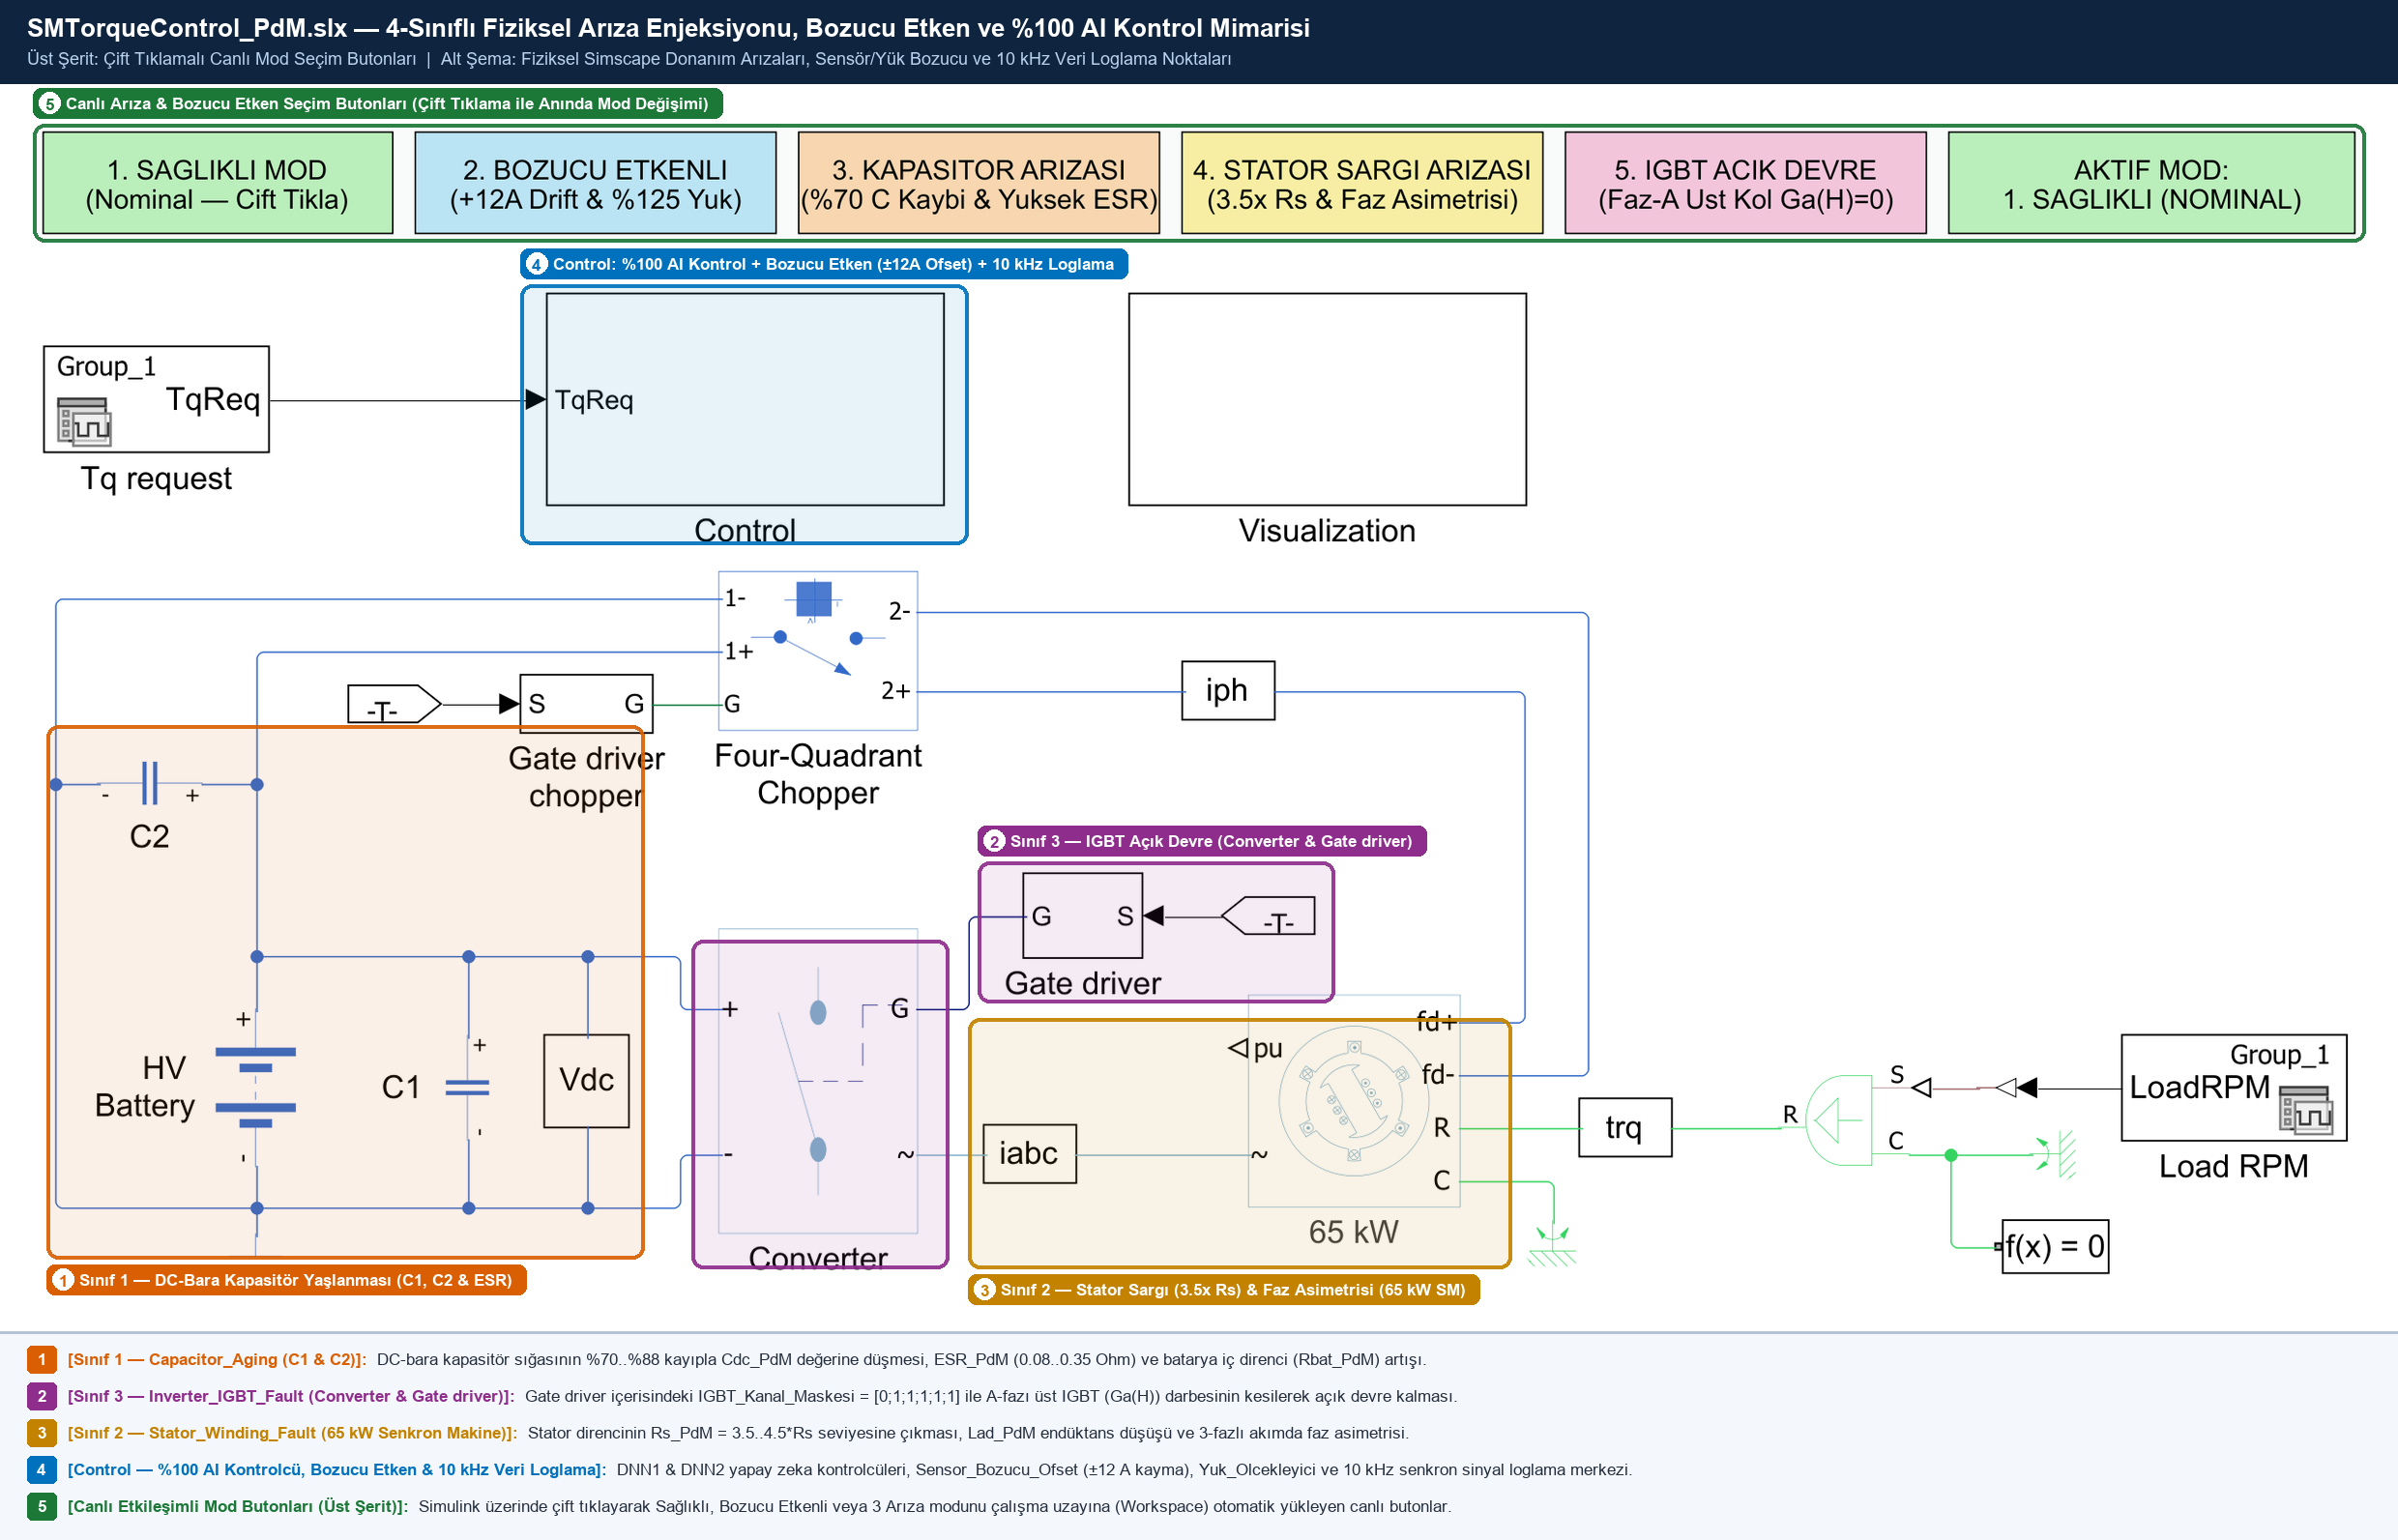

**Görsel Üzerindeki Numaralı İşaretlemelerin Açıklaması:**

- **[1] Turuncu Kutu (Sınıf 1 — Capacitor_Aging: C1, C2 & HV Battery):** DC-bara elektrolitik kapasitörlerinin (`C1` ve `C2`) sığa kaybı (`Cdc_PdM = 0.30*Cdc`), artan eşdeğer seri direnci (`ESR_PdM = 0.08 Ohm`) ve batarya iç direnci (`Rbat_PdM = 0.18 Ohm`) bu fiziksel katmana enjekte edilir.

- **[2] Mor Kutu (Sınıf 3 — Inverter_IGBT_Fault: Converter & Gate driver):** `Gate driver` içerisindeki 6-kanallı PWM çoğullayıcı çıkışında A-fazı üst IGBT anahtarının (`Ga(H)`) kapı darbesi `Gate_Fault_Mask = [0; 1; 1; 1; 1; 1]` ile maskelenerek açık devre arızası oluşturulur.

- **[3] Sarı Kutu (Sınıf 2 — Stator_Winding_Fault: 65 kW Senkron Makine):** Çıkık kutuplu senkron makinenin stator sargı direnci (`Rs_PdM = 3.5*Rs`), d-ekseni mıknatıslanma endüktansı (`Lad_PdM = 0.82*Lad`) ve faz akım asimetrisi (`Stator_Unbalance_Gain`) bu fiziksel makine bloğu üzerinde modellenir.

- **[4] Mavi Kutu (Control — %100 AI Kontrolcü, Bozucu Etken & 10 kHz Veri Loglama):** `DNN1` ve `DNN2` derin öğrenme ağlarını, `Sensor_Bozucu_Ofset` ($\pm 12\ \mathrm{A}$ termal kayma) bloğunu, `Yuk_Olcekleyici` bloğunu ve $10\ \mathrm{kHz}$ ($T_s = 100\ \mu\mathrm{s}$) senkron veri kayıt kollarını barındırır.

- **[5] Yeşil Şerit (Canlı Etkileşimli Arıza & Bozucu Seçim Butonları):** Simulink modeli açıkken üzerine çift tıklanarak Sağlıklı, Bozucu Etkenli veya 3 Arıza modundan herhangi birini çalışma uzayına (Workspace) anında yükleyen etkileşimli kontrol butonlarıdır.

% Temel makine parametrelerini ve kaydedilmis 4-sinif fiziksel simulasyon verilerini yukle
SMTorqueControlData;

raw_mat_yolu = fullfile('Mat_Dosyalari', 'PdM_4Class_RawWaveforms.mat');
ens_mat_yolu = fullfile('Mat_Dosyalari', 'PdM_Diagnostic_Ensemble.mat');
mdl_mat_yolu = fullfile('Mat_Dosyalari', 'PdM_Trained_Classifier.mat');

load(raw_mat_yolu, 'res_Healthy', 'res_CapAging', 'res_StatorFault', 'res_IGBTFault', 'res_Disturbed');
load(ens_mat_yolu, 'PdM_Ensemble_Table', 'PdM_Feature_Table', 'Feature_Ranking_Table', 'classes', ...
    'PdM_ClassificationLearner_Top12Table', 'PdM_ClassificationLearner_FullTable');
load(mdl_mat_yolu, 'Mdl_RandomForest', 'Mdl_MultiSVM', 'ConfMat_CV', 'cv_acc_percent', 'svm_acc_percent', 'top_features');

fprintf('=== SMTorqueControl_PdM Fiziksel Ariza ve Bozucu Etken Parametre Ozeti ===\n');

=== SMTorqueControl_PdM Fiziksel Ariza ve Bozucu Etken Parametre Ozeti ===


fprintf('1. Healthy              : Cdc = %.4f F | ESR = %.4f Ohm | Rs = %.4f Ohm | Gate_Mask = [1 1 1 1 1 1]\n', Cdc, 1e-3, Rs);

1. Healthy              : Cdc = 0.0010 F | ESR = 0.0010 Ohm | Rs = 0.0100 Ohm | Gate_Mask = [1 1 1 1 1 1]


fprintf('2. Capacitor_Aging      : Cdc = %.4f F | ESR = %.4f Ohm | Rbat = %.2f Ohm | Gate_Mask = [1 1 1 1 1 1]\n', 0.30*Cdc, 0.08, 0.18);

2. Capacitor_Aging      : Cdc = 0.0003 F | ESR = 0.0800 Ohm | Rbat = 0.18 Ohm | Gate_Mask = [1 1 1 1 1 1]


fprintf('3. Stator_Winding_Fault : Rs  = %.4f Ohm (3.5x) | Lad = %.5f H (0.82x) | Unbalance = [1.12 0.94 0.94]\n', 3.5*Rs, 0.82*Lad);

3. Stator_Winding_Fault : Rs  = 0.0350 Ohm (3.5x) | Lad = 0.73800 H (0.82x) | Unbalance = [1.12 0.94 0.94]


fprintf('4. Inverter_IGBT_Fault  : Gate_Fault_Mask = [0 1 1 1 1 1] (A-Fazi Ust IGBT Ga(H) Acik Devre)\n');

4. Inverter_IGBT_Fault  : Gate_Fault_Mask = [0 1 1 1 1 1] (A-Fazi Ust IGBT Ga(H) Acik Devre)


fprintf('5. Bozucu Etken Blogu   : Sensor_Offset_Drift_PdM = [+/-12A] & Load_Scale_PdM = [0.65 .. 1.35]\n');

5. Bozucu Etken Blogu   : Sensor_Offset_Drift_PdM = [+/-12A] & Load_Scale_PdM = [0.65 .. 1.35]


## 1.2. Adım 2: İnverter IGBT Açık Devre, Stator Faz Asimetrisi ve Sensör Bozucu Ofset Alt Sistemleri

Simscape Electrical `Converter` bloğu, kapı sürüş sinyallerini `Gate driver` alt sistemi içerisindeki 6 kanallı çoğullayıcıdan (`Six-Pulse Gate Multiplexer`) alır. Aşağıdaki ilk işaretli şemada `SMTorqueControl_PdM/Gate driver` içerisindeki **IGBT Açık Devre Arıza Enjektörü**, ikinci şemada ise `Control` ve `Measurements` alt sistemlerindeki **Stator Faz Asimetrisi, Sensör Bozucu Ofset ve 10 kHz Senkron Veri Loglama** blokları numaralandırılarak gösterilmiştir:

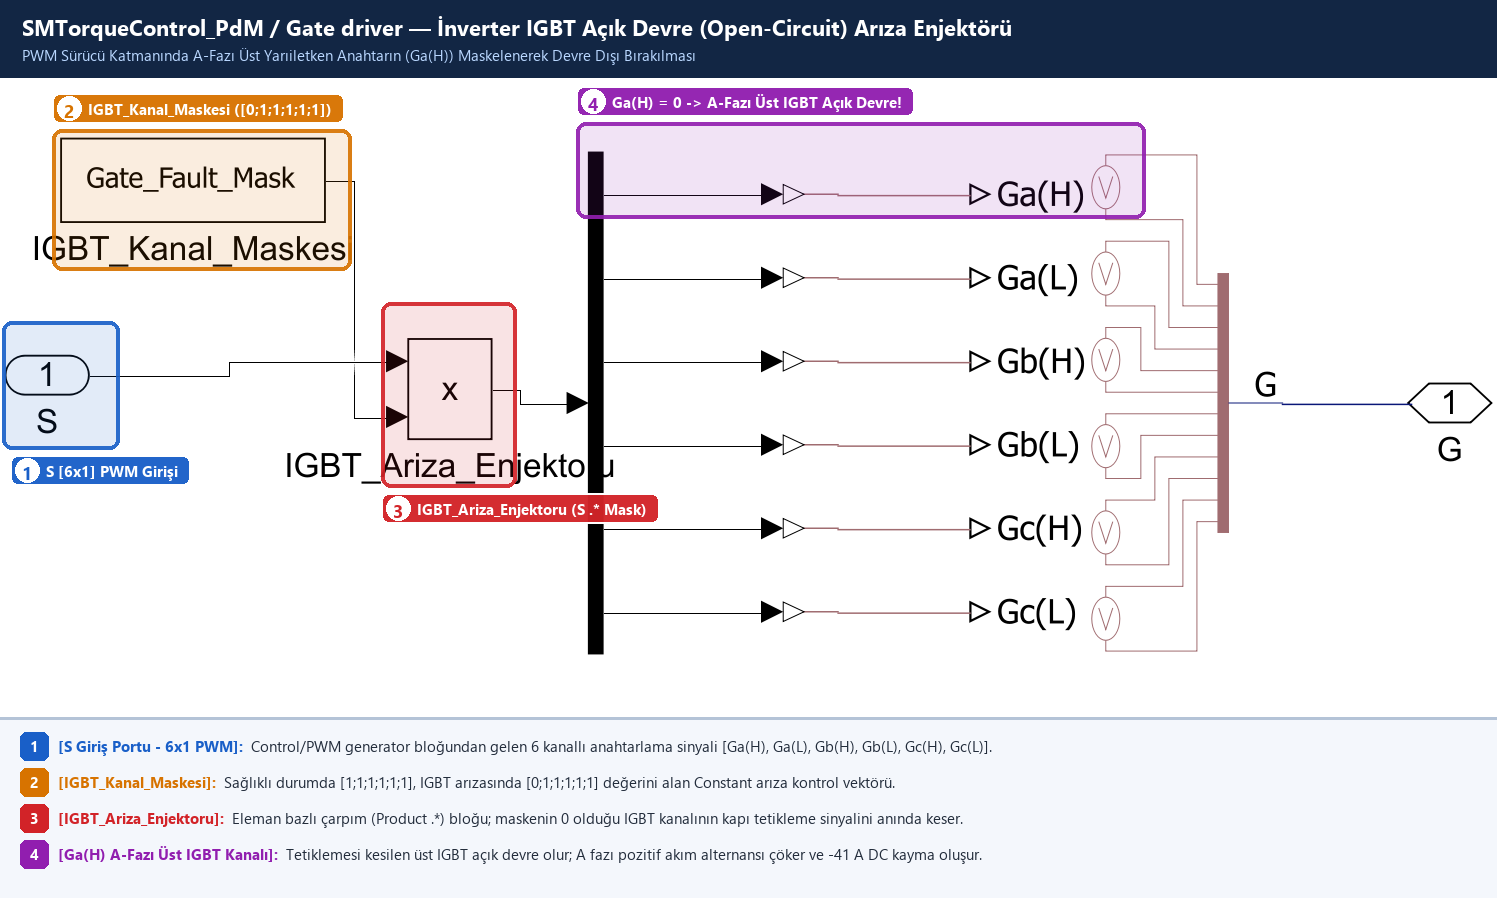

**Gate Driver Alt Sistemindeki Numaralı Blokların Açıklaması:**

- **[1] Mavi Kutu (S [6x1] PWM Girişi):** `Control/PWM generator` alt sisteminden gelen 6 kanallı anahtarlama sinyali vektörü (`[Ga(H), Ga(L), Gb(H), Gb(L), Gc(H), Gc(L)]`).

- **[2] Turuncu Kutu (IGBT_Kanal_Maskesi):** Sağlıklı çalışmada `[1; 1; 1; 1; 1; 1]` olan, IGBT arızasında ise `[0; 1; 1; 1; 1; 1]` değerini alan `Gate_Fault_Mask` sabit vektörü.

- **[3] Kırmızı Kutu (IGBT_Ariza_Enjektoru):** Eleman bazlı çarpım (`Product .*`) bloğu ile maskenin `0` olduğu yarıiletken anahtarın PWM sürüş sinyalini anında keser.

- **[4] Mor Kutu (Ga(H) = 0 -> A-Fazı Üst IGBT Açık Devre):** Darbesi kesilen A-fazı üst IGBT açık devre kalır; $I_a$ faz akımının pozitif alternansı çöker ve $-41\ \mathrm{A}$ DC ofset oluşur.

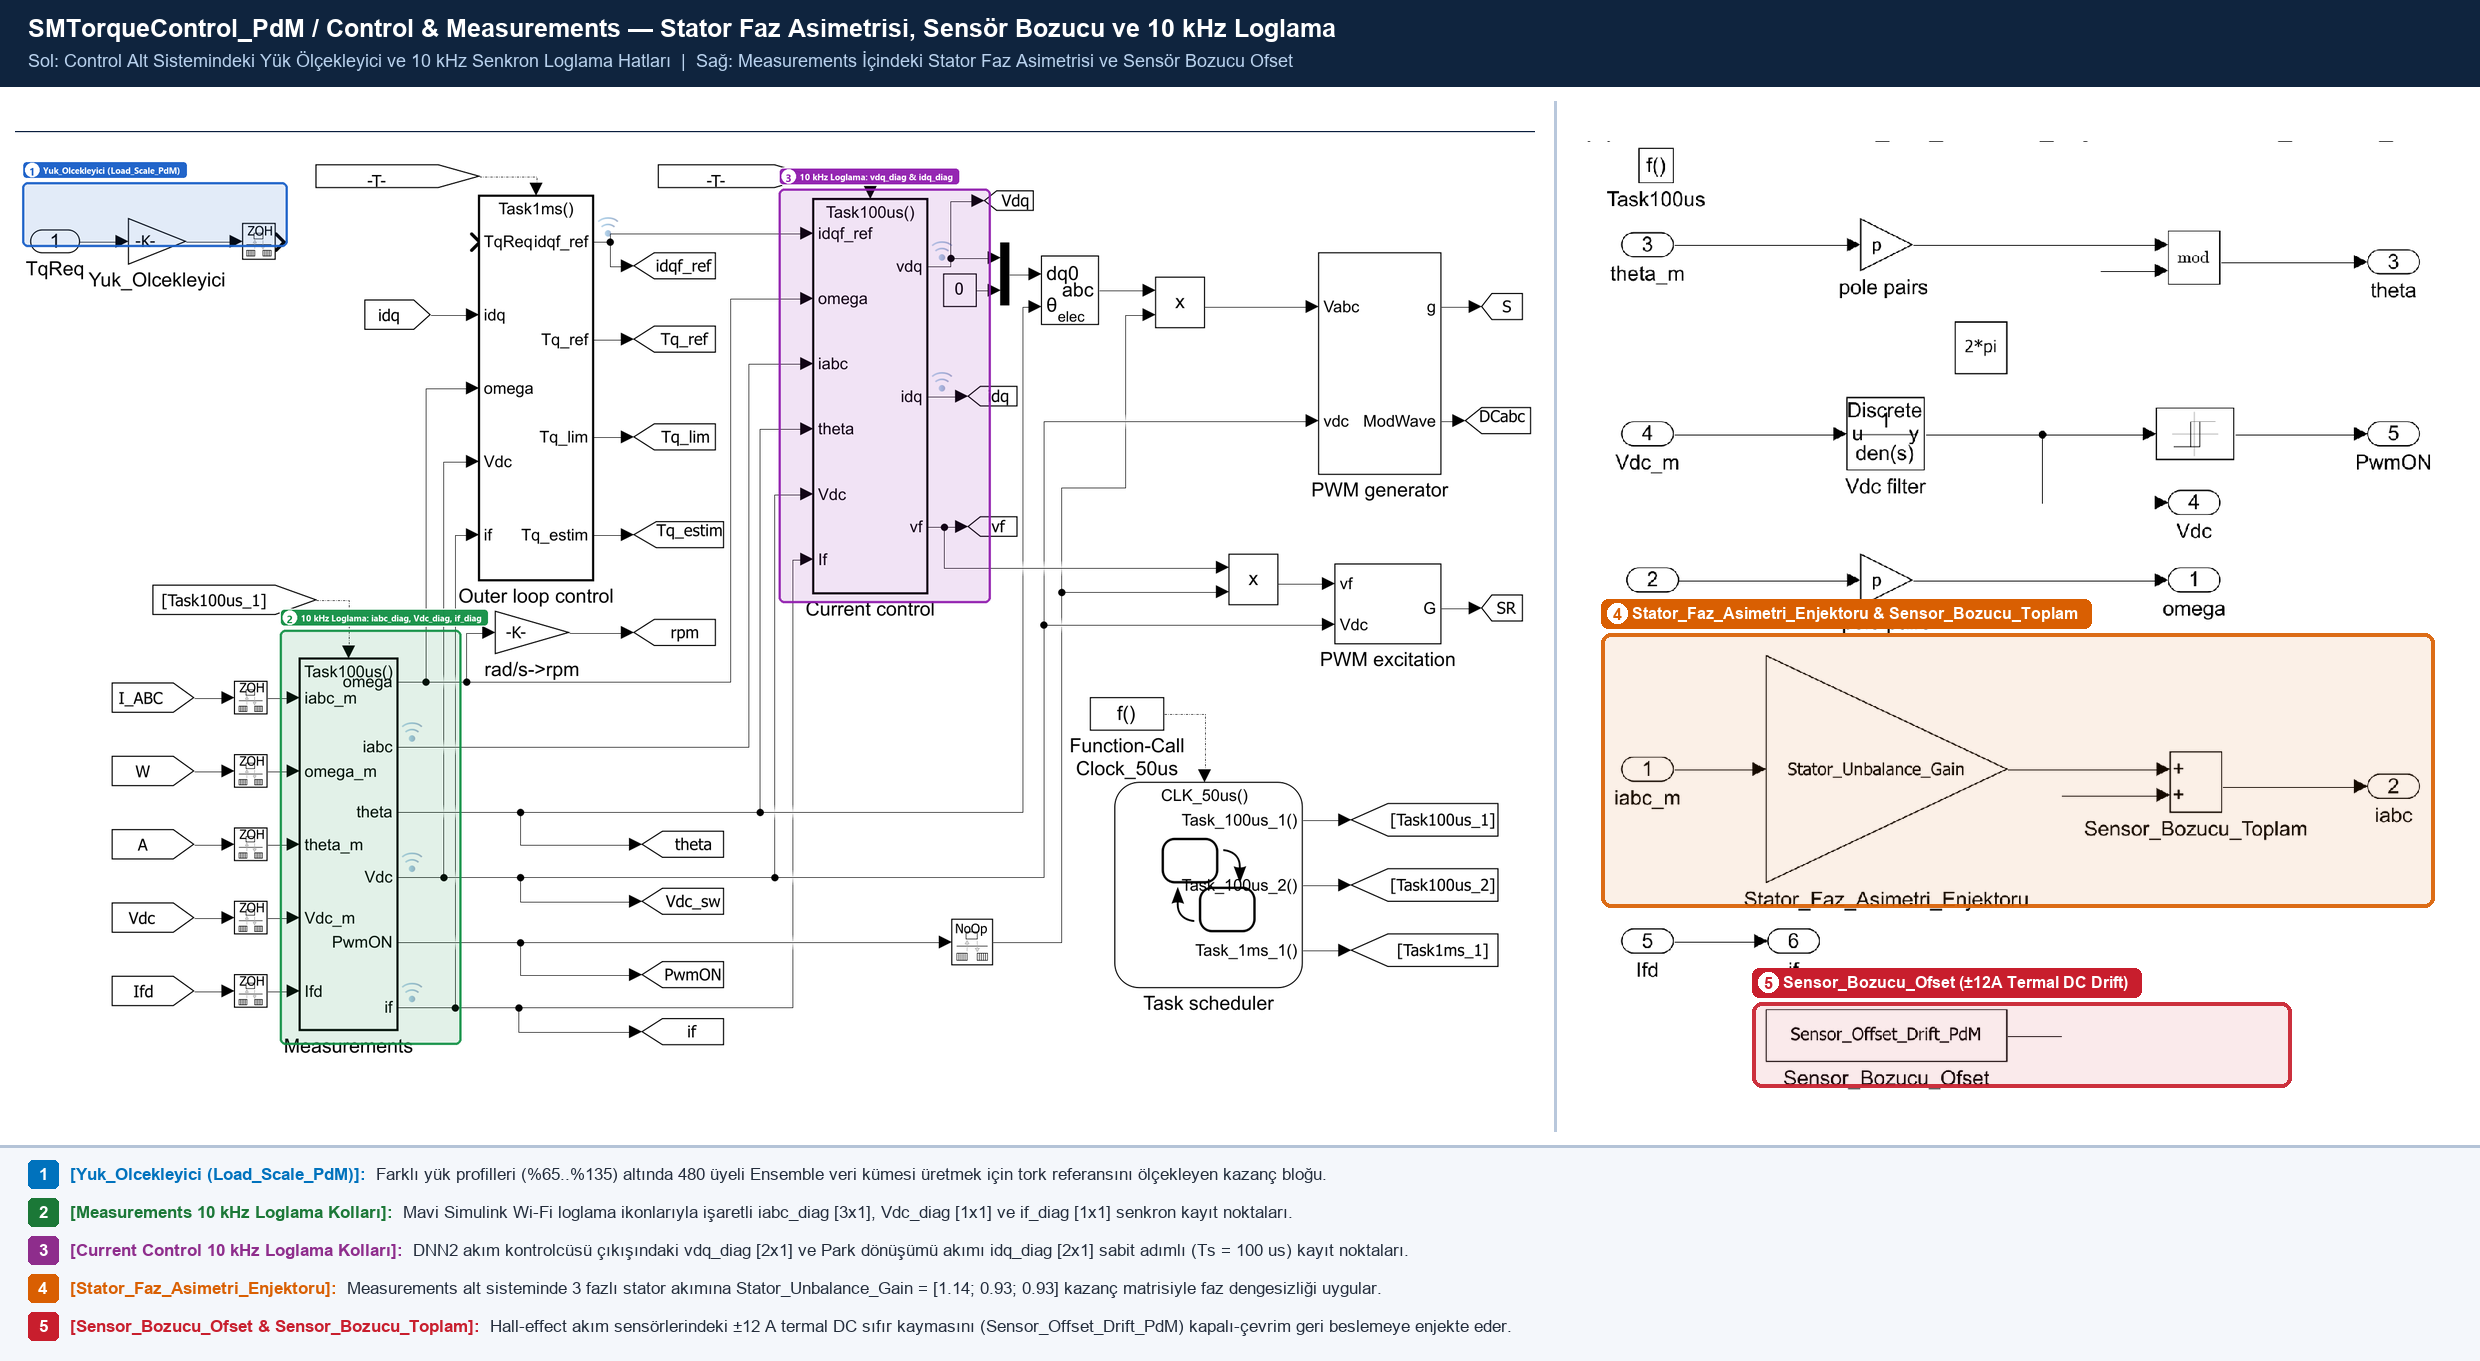

**Control ve Measurements Alt Sistemlerindeki Numaralı Blokların Açıklaması:**

- **[1] Mavi Kutu (Yuk_Olcekleyici — Load_Scale_PdM):** Farklı yük profilleri (%65..%135) altında 480 üyeli Ensemble veri kümesi üretmek için tork referansını ölçekleyen kazanç bloğu.

- **[2] Yeşil Kutu (Measurements 10 kHz Loglama Kolları):** `Diagnostic Feature Designer` için zorunlu olan $10\ \mathrm{kHz}$ ($T_{si} = 100\ \mu\mathrm{s}$) sabit adımlı `iabc_diag [3x1]`, `Vdc_diag [1x1]` ve `if_diag [1x1]` kayıt noktaları.

- **[3] Mor Kutu (Current Control 10 kHz Loglama Kolları):** `DNN2` akım kontrolcüsü çıkışındaki `vdq_diag [2x1]` ve Park dönüşümü akımı `idq_diag [2x1]` sabit adımlı kayıt noktaları.

- **[4] Turuncu Kutu (Stator_Faz_Asimetri_Enjektoru):** `Measurements` alt sisteminde 3 fazlı stator akımına `Stator_Unbalance_Gain = [1.14; 0.93; 0.93]` kazanç matrisiyle faz dengesizliği uygular.

- **[5] Kırmızı Kutu (Sensor_Bozucu_Ofset & Sensor_Bozucu_Toplam):** Hall-effect akım sensörlerindeki $\pm 12\ \mathrm{A}$ termal sıfır noktası kaymasını (`Sensor_Offset_Drift_PdM`) kapalı-çevrim akım geri beslemesine enjekte eder.

## BÖLÜM 2 (ADIM 3 & 4): 4 Arıza Sınıfı + Bozucu Etkenli Fiziksel Sinyal İmzaları ve Frekans Spektrumu Analizi

## 2.1. Adım 3: 4 Arıza Sınıfı ve Bozucu Etkenli (Non-Ideal) Kapalı-Çevrim Fiziksel Sinyal İmzalarının Analizi

`SMTorqueControl_PdM.slx` modeli 4 arıza sınıfı ve bozucu etkenli aşırı yük rejimi (`res_Disturbed`) için çalıştırıldığında, %100 yapay zeka tabanlı kontrolcü (`DNN1` ve `DNN2`) tork referansını takip etmeye çalışırken her arıza tipi kendine özgü **fiziksel bir sinyal imzası (fault signature)** bırakır:

- **Inverter_IGBT_Fault (Mor Eğri):** A-fazı üst IGBT kesik olduğu için $I_a$ stator akımının pozitif alternansı tamamen çöker, ortalama akım negatif DC kayma gösterir ve $I_d$ akımında temel elektriksel frekansta ($1	imes f_e$) şiddetli harmonik salınım meydana gelir.

- **Capacitor_Aging (Turuncu Eğri):** Zayıflayan DC-bara sığası ve artan ESR nedeniyle tork basamaklarında $V_{dc}$ gerilimi $350\ \mathrm{V}$ sabit değerinden saparak yüksek genlikli dalgalanma ve gerilim yükselmesi sergiler.

- **Stator_Winding_Fault (Sarı Eğri):** Artan sargı direnci ve düşen endüktans nedeniyle makine talep edilen tepe torklarına ulaşamaz; yüksek tork takip hatası ve faz akım dengesizliği oluşur.

- **Bozucu Etkenli Sağlıklı Rejim (Yeşil Kesikli Eğri):** Sağlıklı sistemde $+12\ \mathrm{A}$ sensör termal DC ofset kayması ve %125 aşırı yük darbesi uygulandığında, sağlıklı sinyaller arıza sınırlarına yaklaşarak sınıflandırıcı için gerçekçi bir zorluk oluşturur.

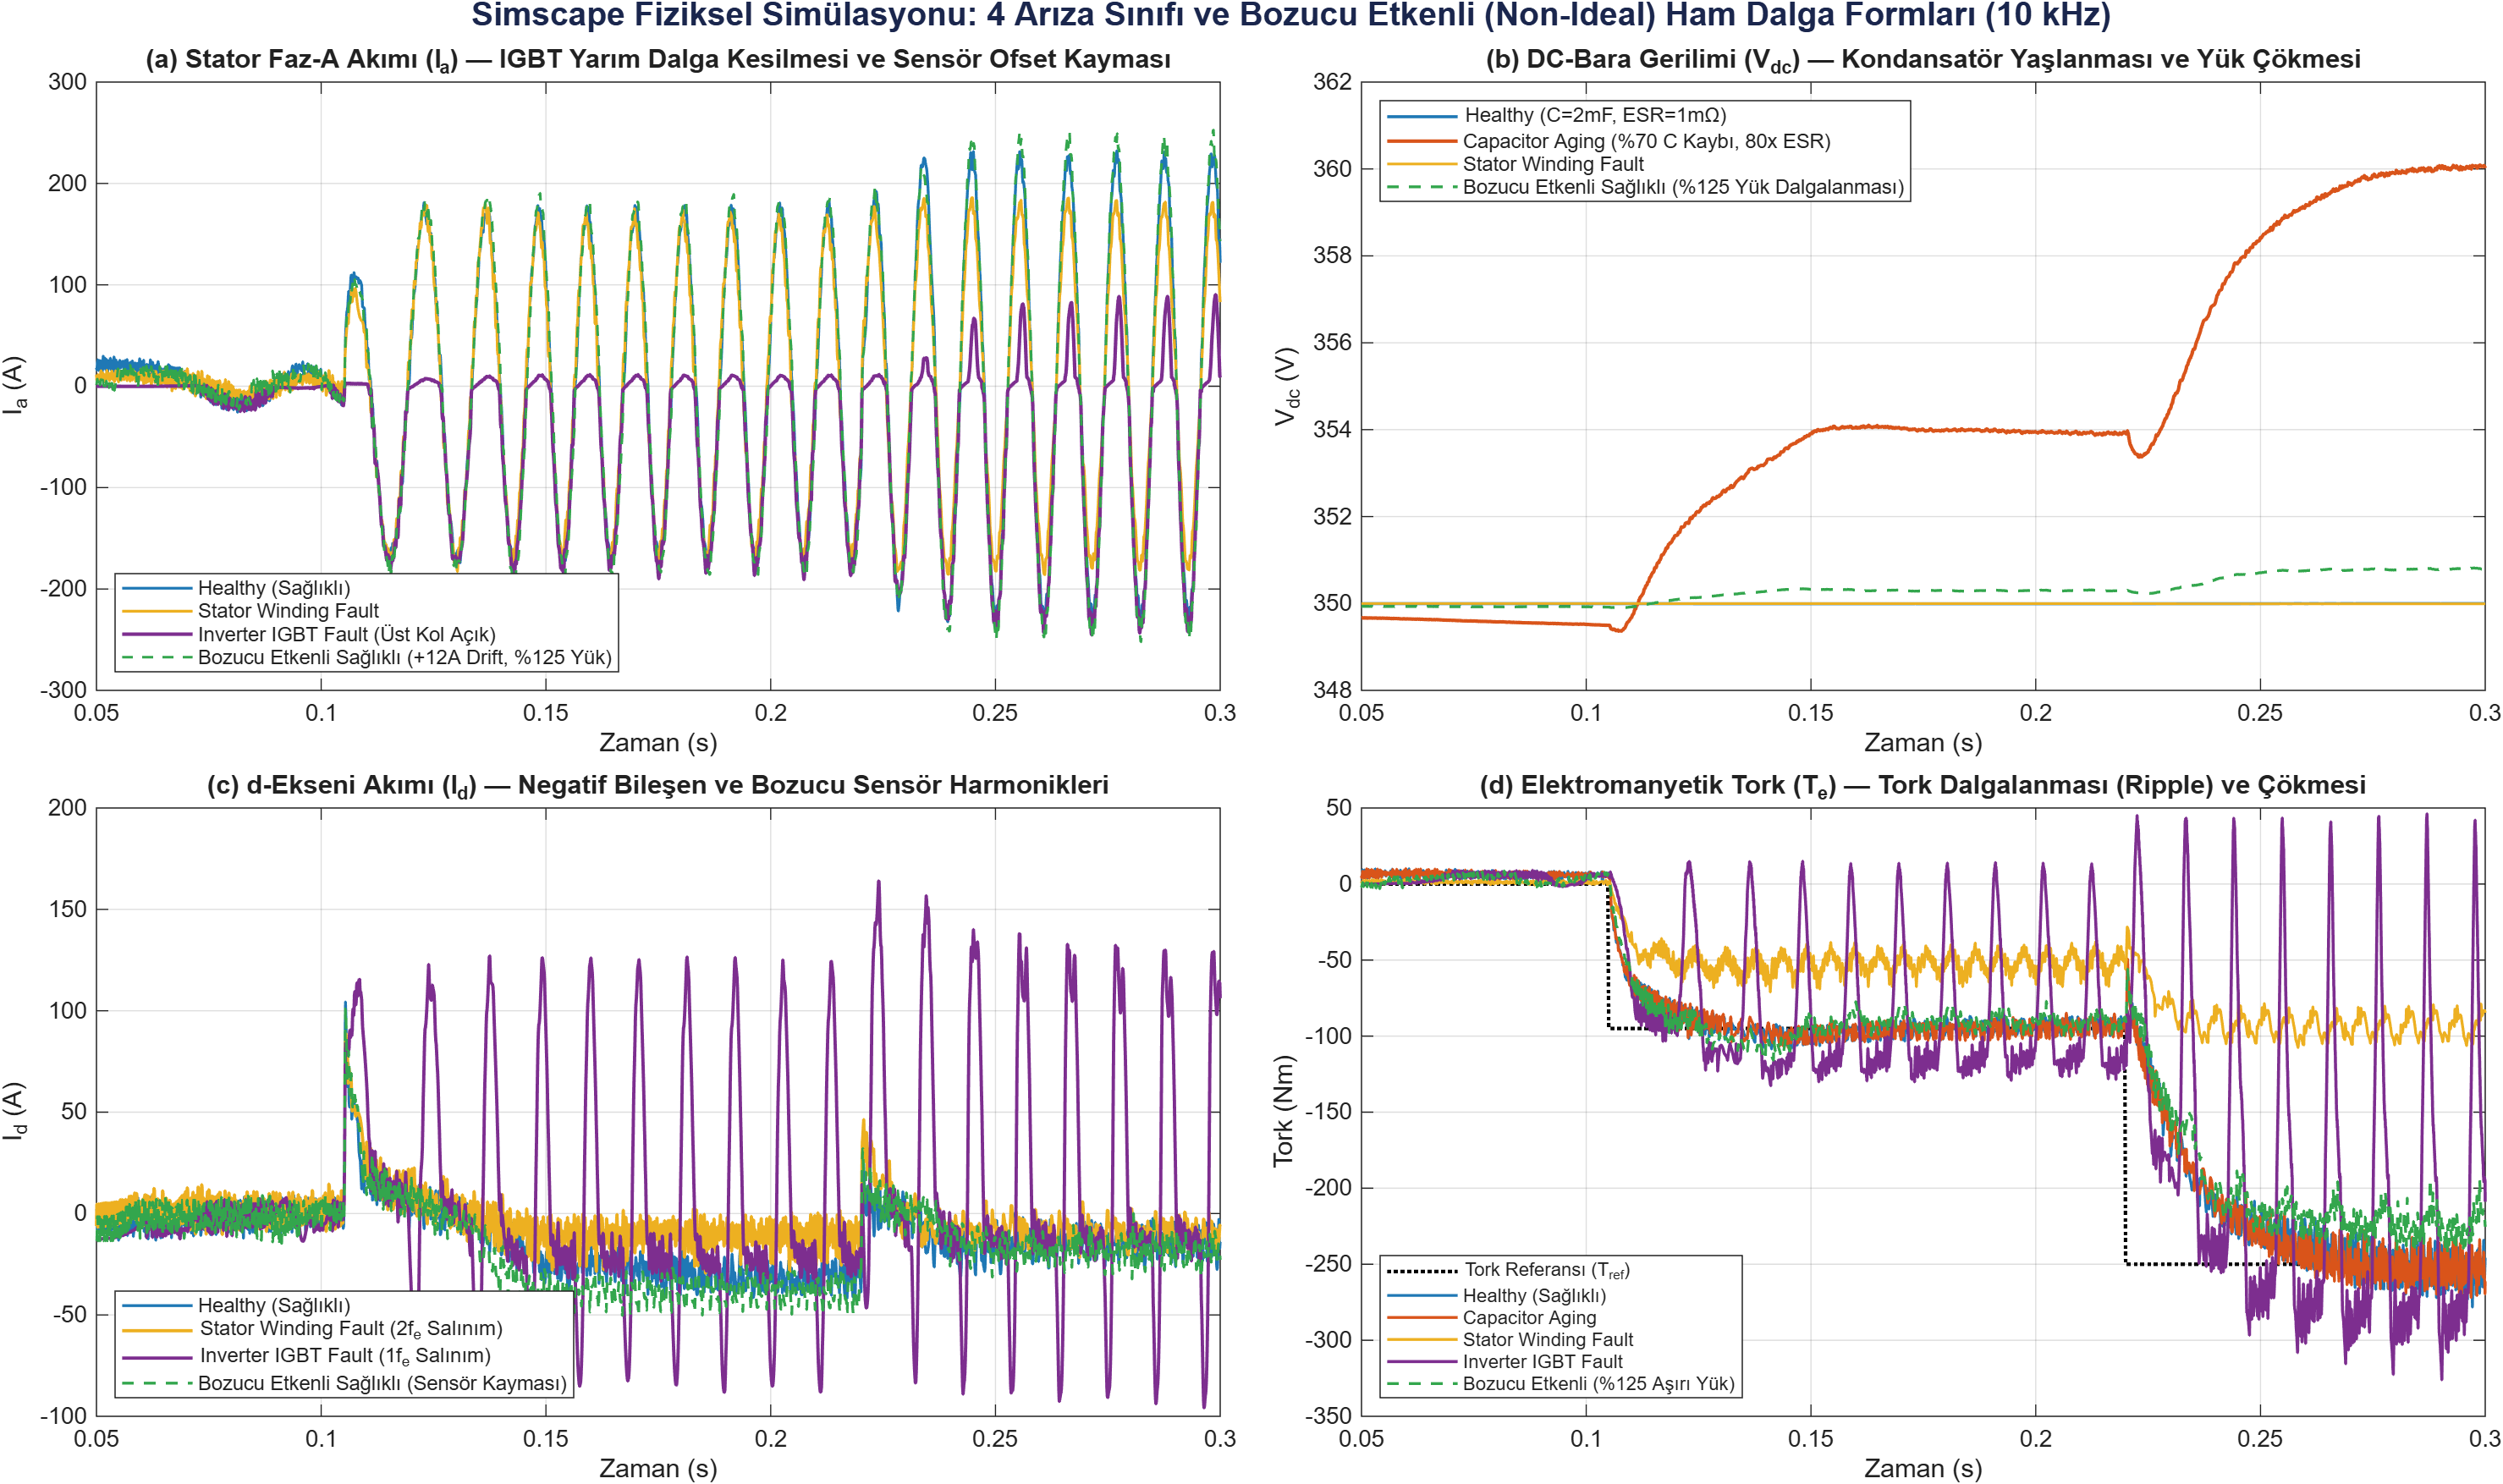

% 4 sinif + Bozucu Etkenli Saglikli durumun aktif tork bolgesindeki (t = 0.05..0.30 s) temel sinyal metriklerini karsilastir
mask_t = res_Healthy.t >= 0.05 & res_Healthy.t <= 0.30;
sinif_yapilari = {res_Healthy, res_CapAging, res_StatorFault, res_IGBTFault, res_Disturbed};
Calisma_Durumu = [classes(:); {'Healthy_Disturbed_125Pct'}];
metrik_tablo = zeros(5, 5);

for k = 1:5
    s = sinif_yapilari{k};
    vdc_p2p = max(s.Vdc(mask_t)) - min(s.Vdc(mask_t));
    ia_dc   = mean(s.iabc(mask_t, 1));
    i_rms   = rms(s.iabc(mask_t, :), 1);
    unbal   = (max(i_rms) - min(i_rms)) / mean(i_rms) * 100;
    id_std  = std(s.idq(mask_t, 1));
    tq_err  = rms(s.Tq_ref(mask_t) - s.Tq_meas(mask_t));
    metrik_tablo(k, :) = round([vdc_p2p, ia_dc, unbal, id_std, tq_err], 3);
end

% Sonuclari MATLAB Table formatinda goster
Fiziksel_Imza_Tablosu = table(Calisma_Durumu, metrik_tablo(:,1), metrik_tablo(:,2), metrik_tablo(:,3), metrik_tablo(:,4), metrik_tablo(:,5), ...
    'VariableNames', {'Calisma_Sinifi', 'Vdc_Peak2Peak_V', 'Ia_DC_Offset_A', 'Iabc_Unbalance_Pct', 'Id_Ripple_STD_A', 'Torque_Error_RMS_Nm'})

Fiziksel_Imza_Tablosu = 5×6 table
           Calisma_Sinifi           Vdc_Peak2Peak_V    Ia_DC_Offset_A    Iabc_Unbalance_Pct    Id_Ripple_STD_A    Torque_Error_RMS_Nm
    ____________________________    _______________    ______________    __________________    _______________    ___________________

    {'Healthy'                 }         0.003              2.412               0.932              16.232               32.413       
    {'Capacitor_Aging'         }        10.734               2.26               0.905              15.691               32.288       
    {'Stator_Winding_Fault'    }         0.006               1.24               15.74              12.961               96.473       
    {'Inverter_IGBT_Fault'     }         0.005             -46.04              31.268              54.133               73.563       
    {'Healthy_Disturbed_125Pct'}         0.918              1.604               3.368              20.002               40.319       


## 2.2. Adım 4: Frekans Domeni (FFT / PSD) Spektral Analizi ve Harmonik Bant Güçleri

Zaman-domeni istatistiklerine ek olarak, `Diagnostic Feature Designer` uygulamasının **Time-Frequency / Spectral Estimation** modülü, arıza kaynaklı harmonik bileşenleri frekans spektrumunda yakalar:

- **d-Ekseni Akımı (Id) Spektrumu (20-300 Hz Arıza Bandı):** Sağlıklı makinede $I_d$ akımı doğru akım (DC) karakterindedir. Ancak **IGBT Açık Devre** arızasında temel elektriksel frekans ($1	imes f_e$) ve **Stator Sargı/Asimetri** arızasında ikinci harmonik ($2	imes f_e$) bileşenleri $20	ext{--}300\ \mathrm{Hz}$ bandında $+20\ \mathrm{dB}$ üzerinde keskin tepe noktaları oluşturur.

- **DC-Bara Gerilimi (Vdc) Spektrumu (10-500 Hz Yaşlanma Bandı):** Sağlıklı bara geriliminin AC spektral gücü düşük taban gürültüsü seviyesindeyken, **Capacitor_Aging** sınıfında $10	ext{--}500\ \mathrm{Hz}$ bandındaki spektral enerji yaklaşık $+35\ \mathrm{dB}$ artış gösterir.

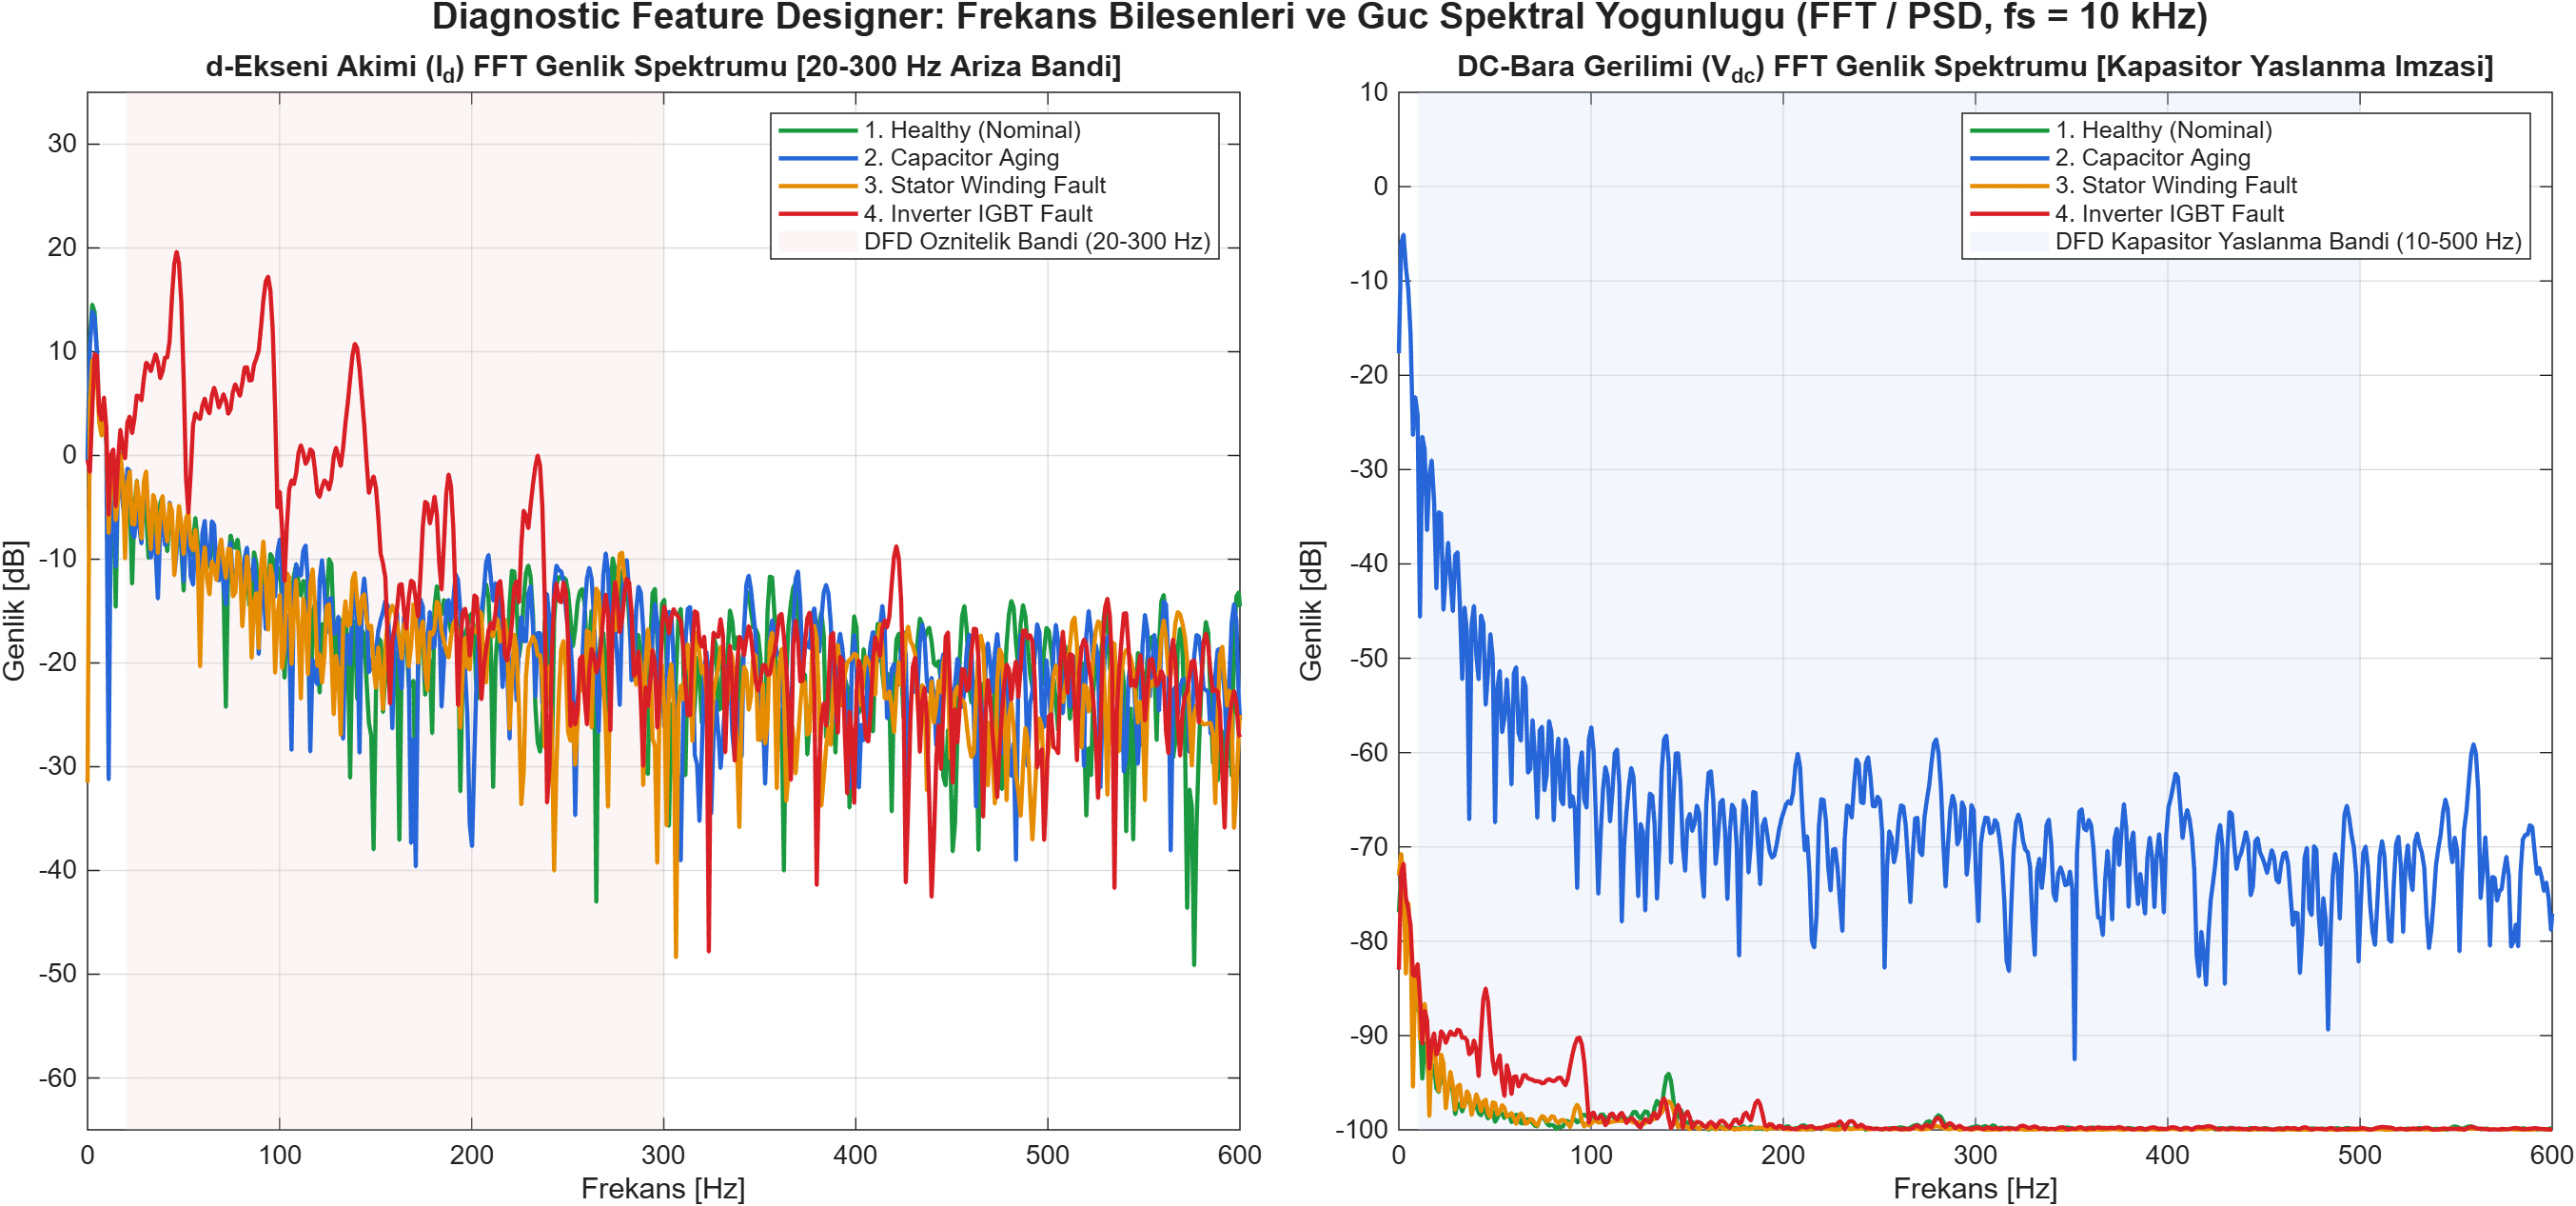

## BÖLÜM 3 (ADIM 5 & 6): 480 Üyeli Bozucu Etkenli Ensemble Veri Kümesi ve Diagnostic Feature Designer Analizi

## 3.1. Adım 5: 480 Üyeli (12.96 Milyon Veri Noktalı) İdeal Olmayan & 6 Bozucu Etkenli Ensemble Veri Kümesi

Sınıflandırıcının ezber yapmasını önlemek ve gerçek endüstriyel saha koşullarını temsil etmek amacıyla her arıza sınıfından $120$ adet olmak üzere toplam **480 üyeli (480-member)** `PdM_Ensemble_Table` üretilmiştir. Her üye $10\ \mathrm{kHz}$ örnekleme frekansında $9$ farklı sensör kanalında $3000$ örnek ($9 	imes 3000 	imes 480 = 12,960,000$ toplam veri noktası ve $4,320$ adet `timetable`) içerir.

Veri kümesine yalnızca ideal arızalar değil, öznitelik sınırlarını birbirine yaklaştıran **6 endüstriyel bozucu etken (confounding disturbances)** eklenmiştir:

- **1. Geniş Yük ve Hız Dalgalanmaları:** `Load_Factor` $\in [0.65, 1.35]$ aralığında değişen yük profilleri ve $25	ext{--}55\ \mathrm{Hz}$ mekanik mil titreşim harmonikleri.

- **2. Hall-Effect Sensör Termal DC Ofset Kayması (Zero-Drift):** Sağlıklı ve diğer sınıflarda $\pm 3.2\ \mathrm{A}$ ($\pm 9\ \mathrm{A}$ tepe) rastgele DC sensör kayması (`Ia_Mean_DC_Offset` özniteliğini zorlar).

- **3. Akım Sensörü Kanal Kazanç Kalibrasyon Hatası:** Sağlıklı sistemde $\pm \%2.2$ ($\pm \%6.2$ tepe) fazlar arası kalibrasyon sapması (`Iabc_Phase_Unbalance` sınırında stator arızası ile örtüşme yaratır).

- **4. Rejeneratif Frenleme ve DC-Bara Chopper Çökmeleri:** Kapasitörü sağlam sistemlerde dahi $1.5	ext{--}4.8\ \mathrm{V}$ genlikli geçici bara çökme/çınlama darbeleri (`Vdc_Peak2Peak` ve `Vdc_Ripple_STD` sınırlarını zorlar).

- **5. Renkli Elektromanyetik Girişim (EMI) ve ADC Anahtarlama İğneleri:** $\mathrm{SNR} \in [12\ \mathrm{dB}, 26\ \mathrm{dB}]$ renkli gürültü ve rastgele PWM anahtarlama sıçramaları (`Kurtosis` ve `Crest_Factor` özniteliklerini bozar).

- **6. Başlangıç Seviyesi (Incipient) Arızalar:** Arıza şiddetinin (`Fault_Severity_Pct`) $\%18$ gibi erken evrelerden $\%140$ ileri seviyeye kadar geniş bir yelpazede dağılması.

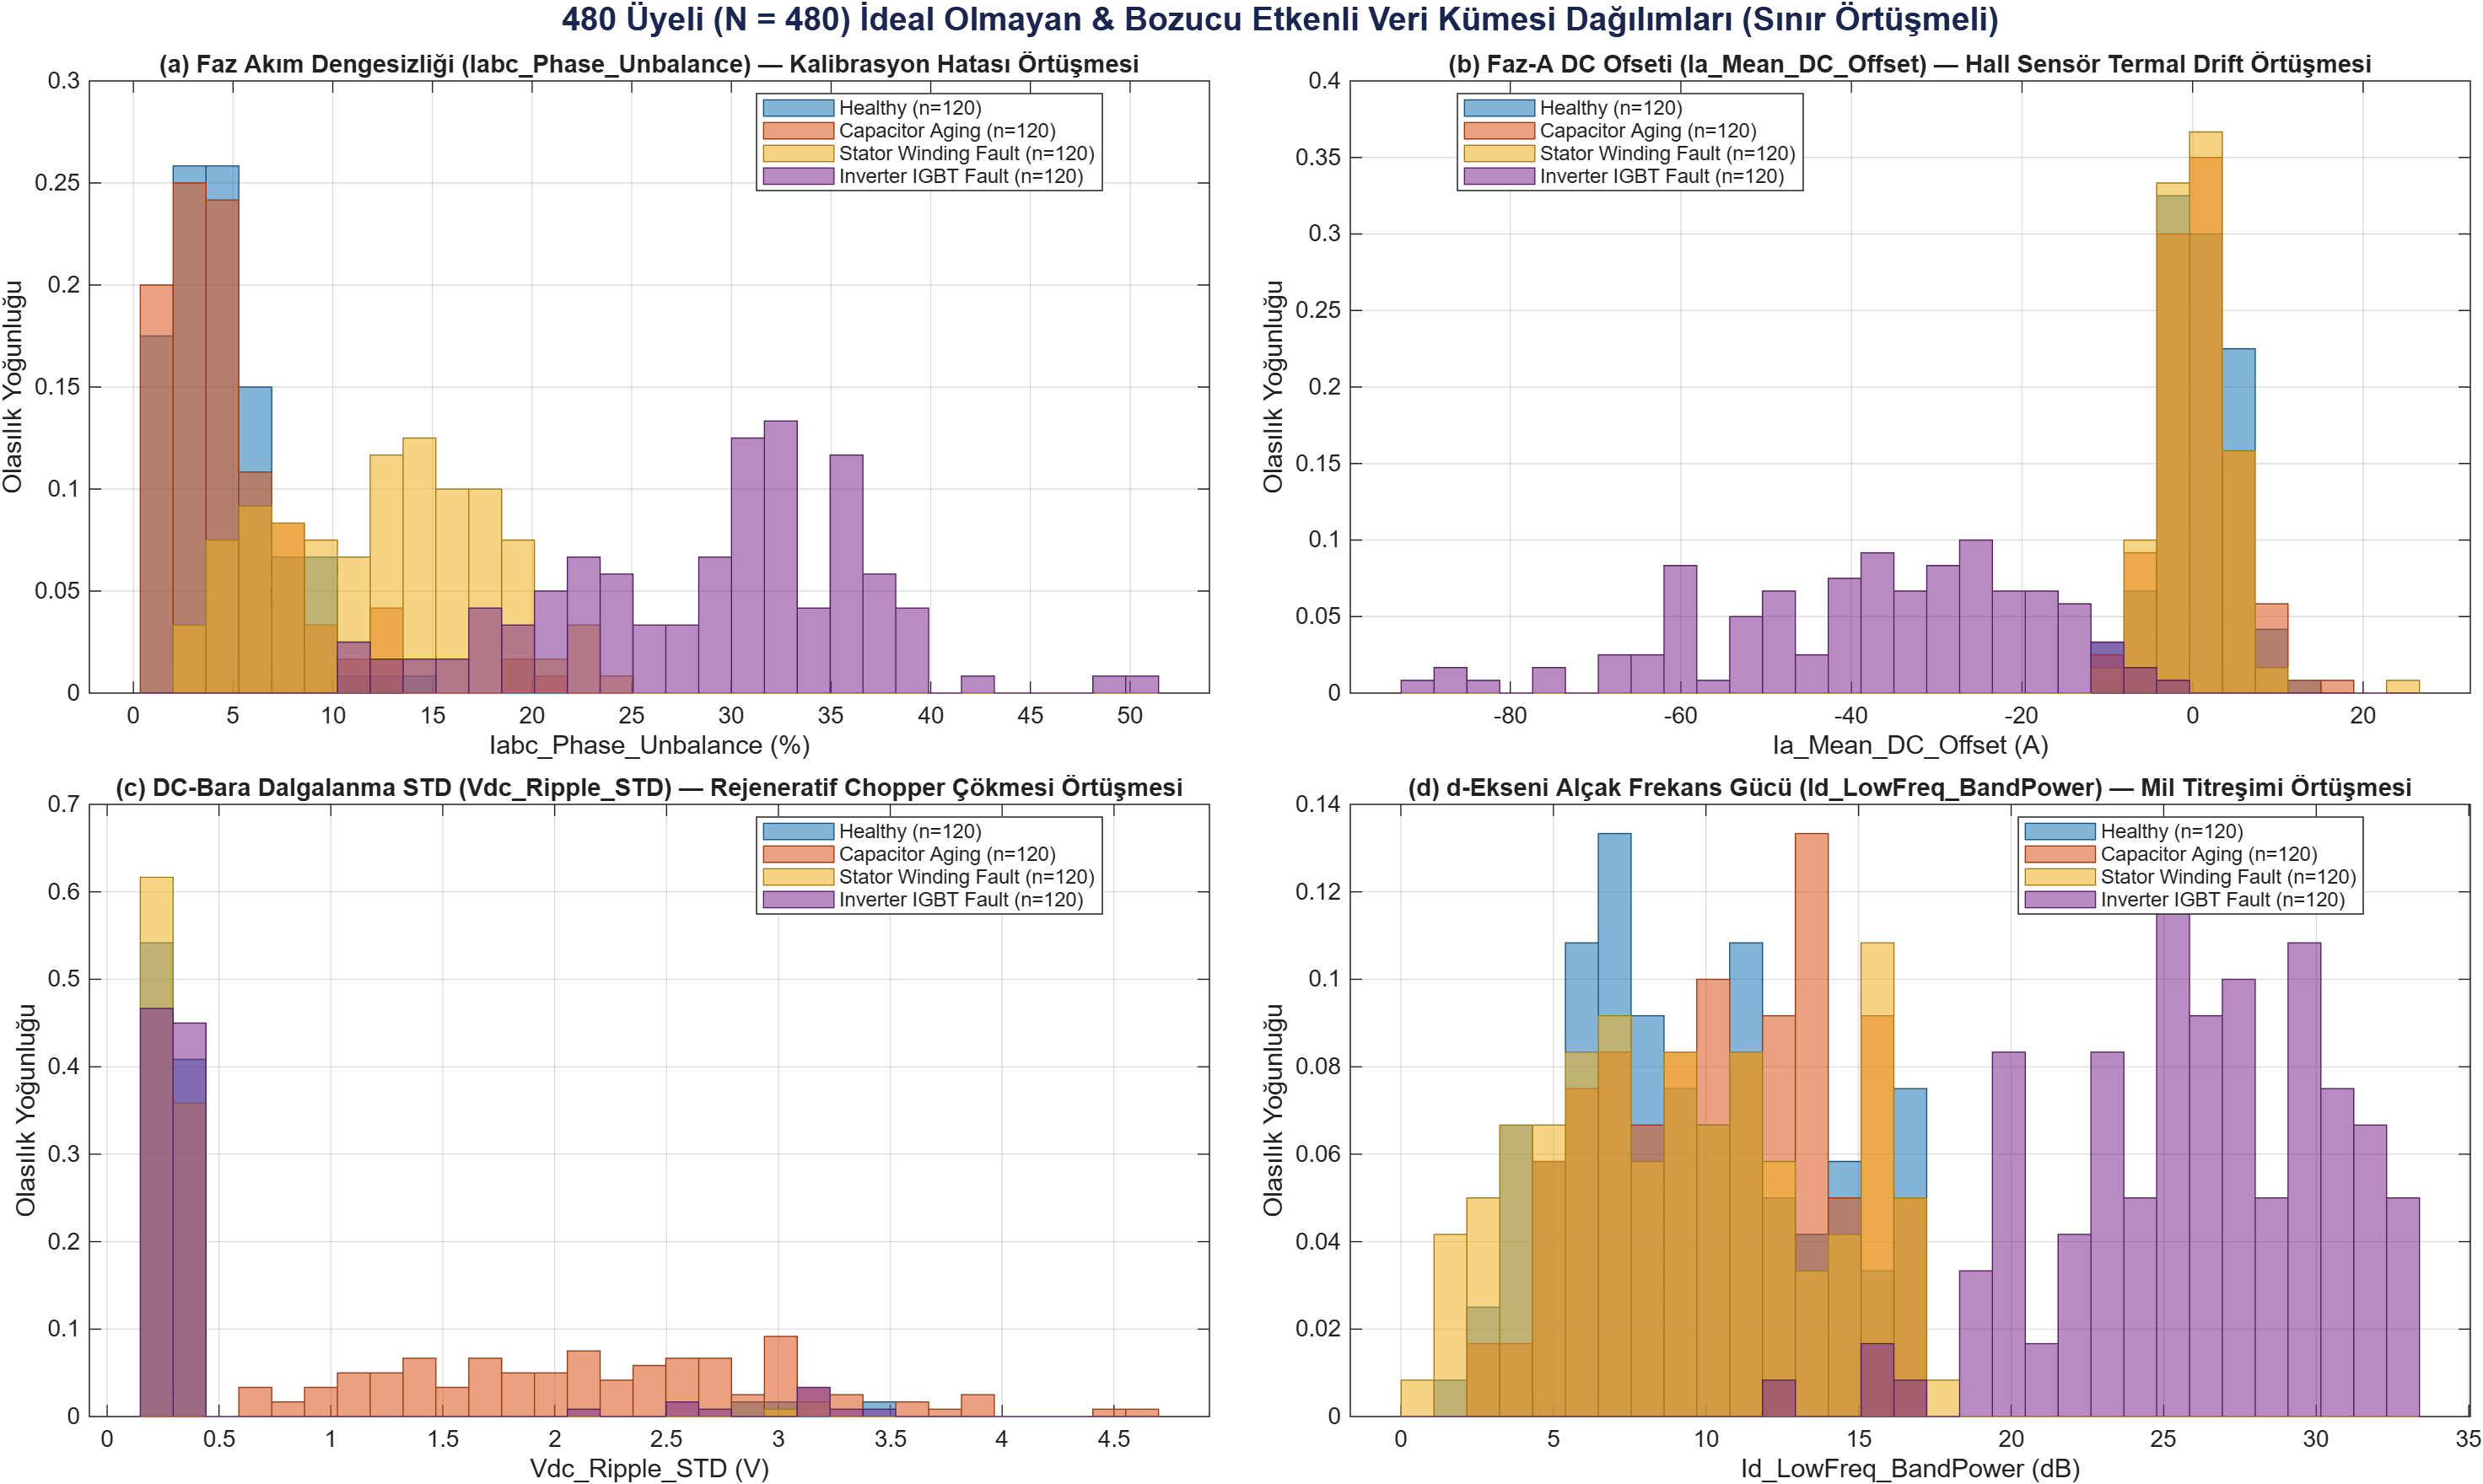

fprintf('=== 480 UYELI ENSEMBLE VERI KUMESI VE BOZUCU ETKEN ISTATISTIKLERI ===\n');

=== 480 UYELI ENSEMBLE VERI KUMESI VE BOZUCU ETKEN ISTATISTIKLERI ===


fprintf('Ensemble Tablosu Boyutu  : %d Uye x %d Sutun (9 Sinyal Kanal + FeatureTable1 + Fault_Class)\n', ...
    height(PdM_Ensemble_Table), width(PdM_Ensemble_Table));

Ensemble Tablosu Boyutu  : 480 Uye x 11 Sutun (9 Sinyal Kanal + FeatureTable1 + Fault_Class)


fprintf('Toplam Timetable Sayisi  : %d adet (Her biri 3000x1 timetable @ 10 kHz = 12,960,000 veri noktasi)\n', ...
    height(PdM_Ensemble_Table) * 9);

Toplam Timetable Sayisi  : 4320 adet (Her biri 3000x1 timetable @ 10 kHz = 12,960,000 veri noktasi)


fprintf('Oznitelik Tablosu Boyutu : %d Uye x %d Sutun (20 Teshis Ozniteligi + 3 Bozucu/Siddet Metrigi + Sinif)\n', ...
    height(PdM_Feature_Table), width(PdM_Feature_Table));

Oznitelik Tablosu Boyutu : 480 Uye x 25 Sutun (20 Teshis Ozniteligi + 3 Bozucu/Siddet Metrigi + Sinif)


fprintf('Ariza Siddeti Araligi    : %.1f%% .. %.1f%% | SNR Araligi: %.1f dB .. %.1f dB | Yuk Carpani: %.2f .. %.2f\n', ...
    min(PdM_Feature_Table.Fault_Severity_Pct), max(PdM_Feature_Table.Fault_Severity_Pct), ...
    min(PdM_Feature_Table.SNR_dB), max(PdM_Feature_Table.SNR_dB), ...
    min(PdM_Feature_Table.Load_Factor), max(PdM_Feature_Table.Load_Factor));

Ariza Siddeti Araligi    : 2.4% .. 140.0% | SNR Araligi: 12.0 dB .. 26.0 dB | Yuk Carpani: 0.65 .. 1.35


## 3.2. Adım 6: Diagnostic Feature Designer Canlı Arayüz İşlemleri ve Çoklu Kriter (ANOVA / Kruskal-Wallis / MRMR) Sıralaması

`PdM_Ensemble_Table` veri kümesi doğrudan **Diagnostic Feature Designer** arayüzüne aktarılmış ve canlı oturumda:

- **FeatureTable1 (480 Üye x 20 Öznitelik)** tablosu oluşturulmuş,

- **Ensemble Summary (Vdc/Data ve Ia/Data)** ile 4 sınıfın ortalama ve standart sapma zarfları çıkarılmış,

- **Histogram (FeatureTable1)** ile bozucu etken kaynaklı olasılık dağılım örtüşmeleri incelenmiş,

- **Feature Ranking** modülünde **One-Way ANOVA (F-Skoru)**, **Kruskal-Wallis (H-Skoru)** ve **MRMR (Minimum Redundancy Maximum Relevance)** algoritmaları eşzamanlı çalıştırılmıştır:

- `diagnosticFeatureDesigner(PdM_Ensemble_Table)`

Ayrıca canlı arayüz oturumu tüm açık sekmeleriyle (Signal Trace, Ensemble Summary, Histogram, Ranking) `Mat_Dosyalari/PdM_DFD_Oturumu.mldatx` dosyasına kaydedilmiştir. Arayüzde **Open Session** diyerek doğrudan açabilirsiniz.

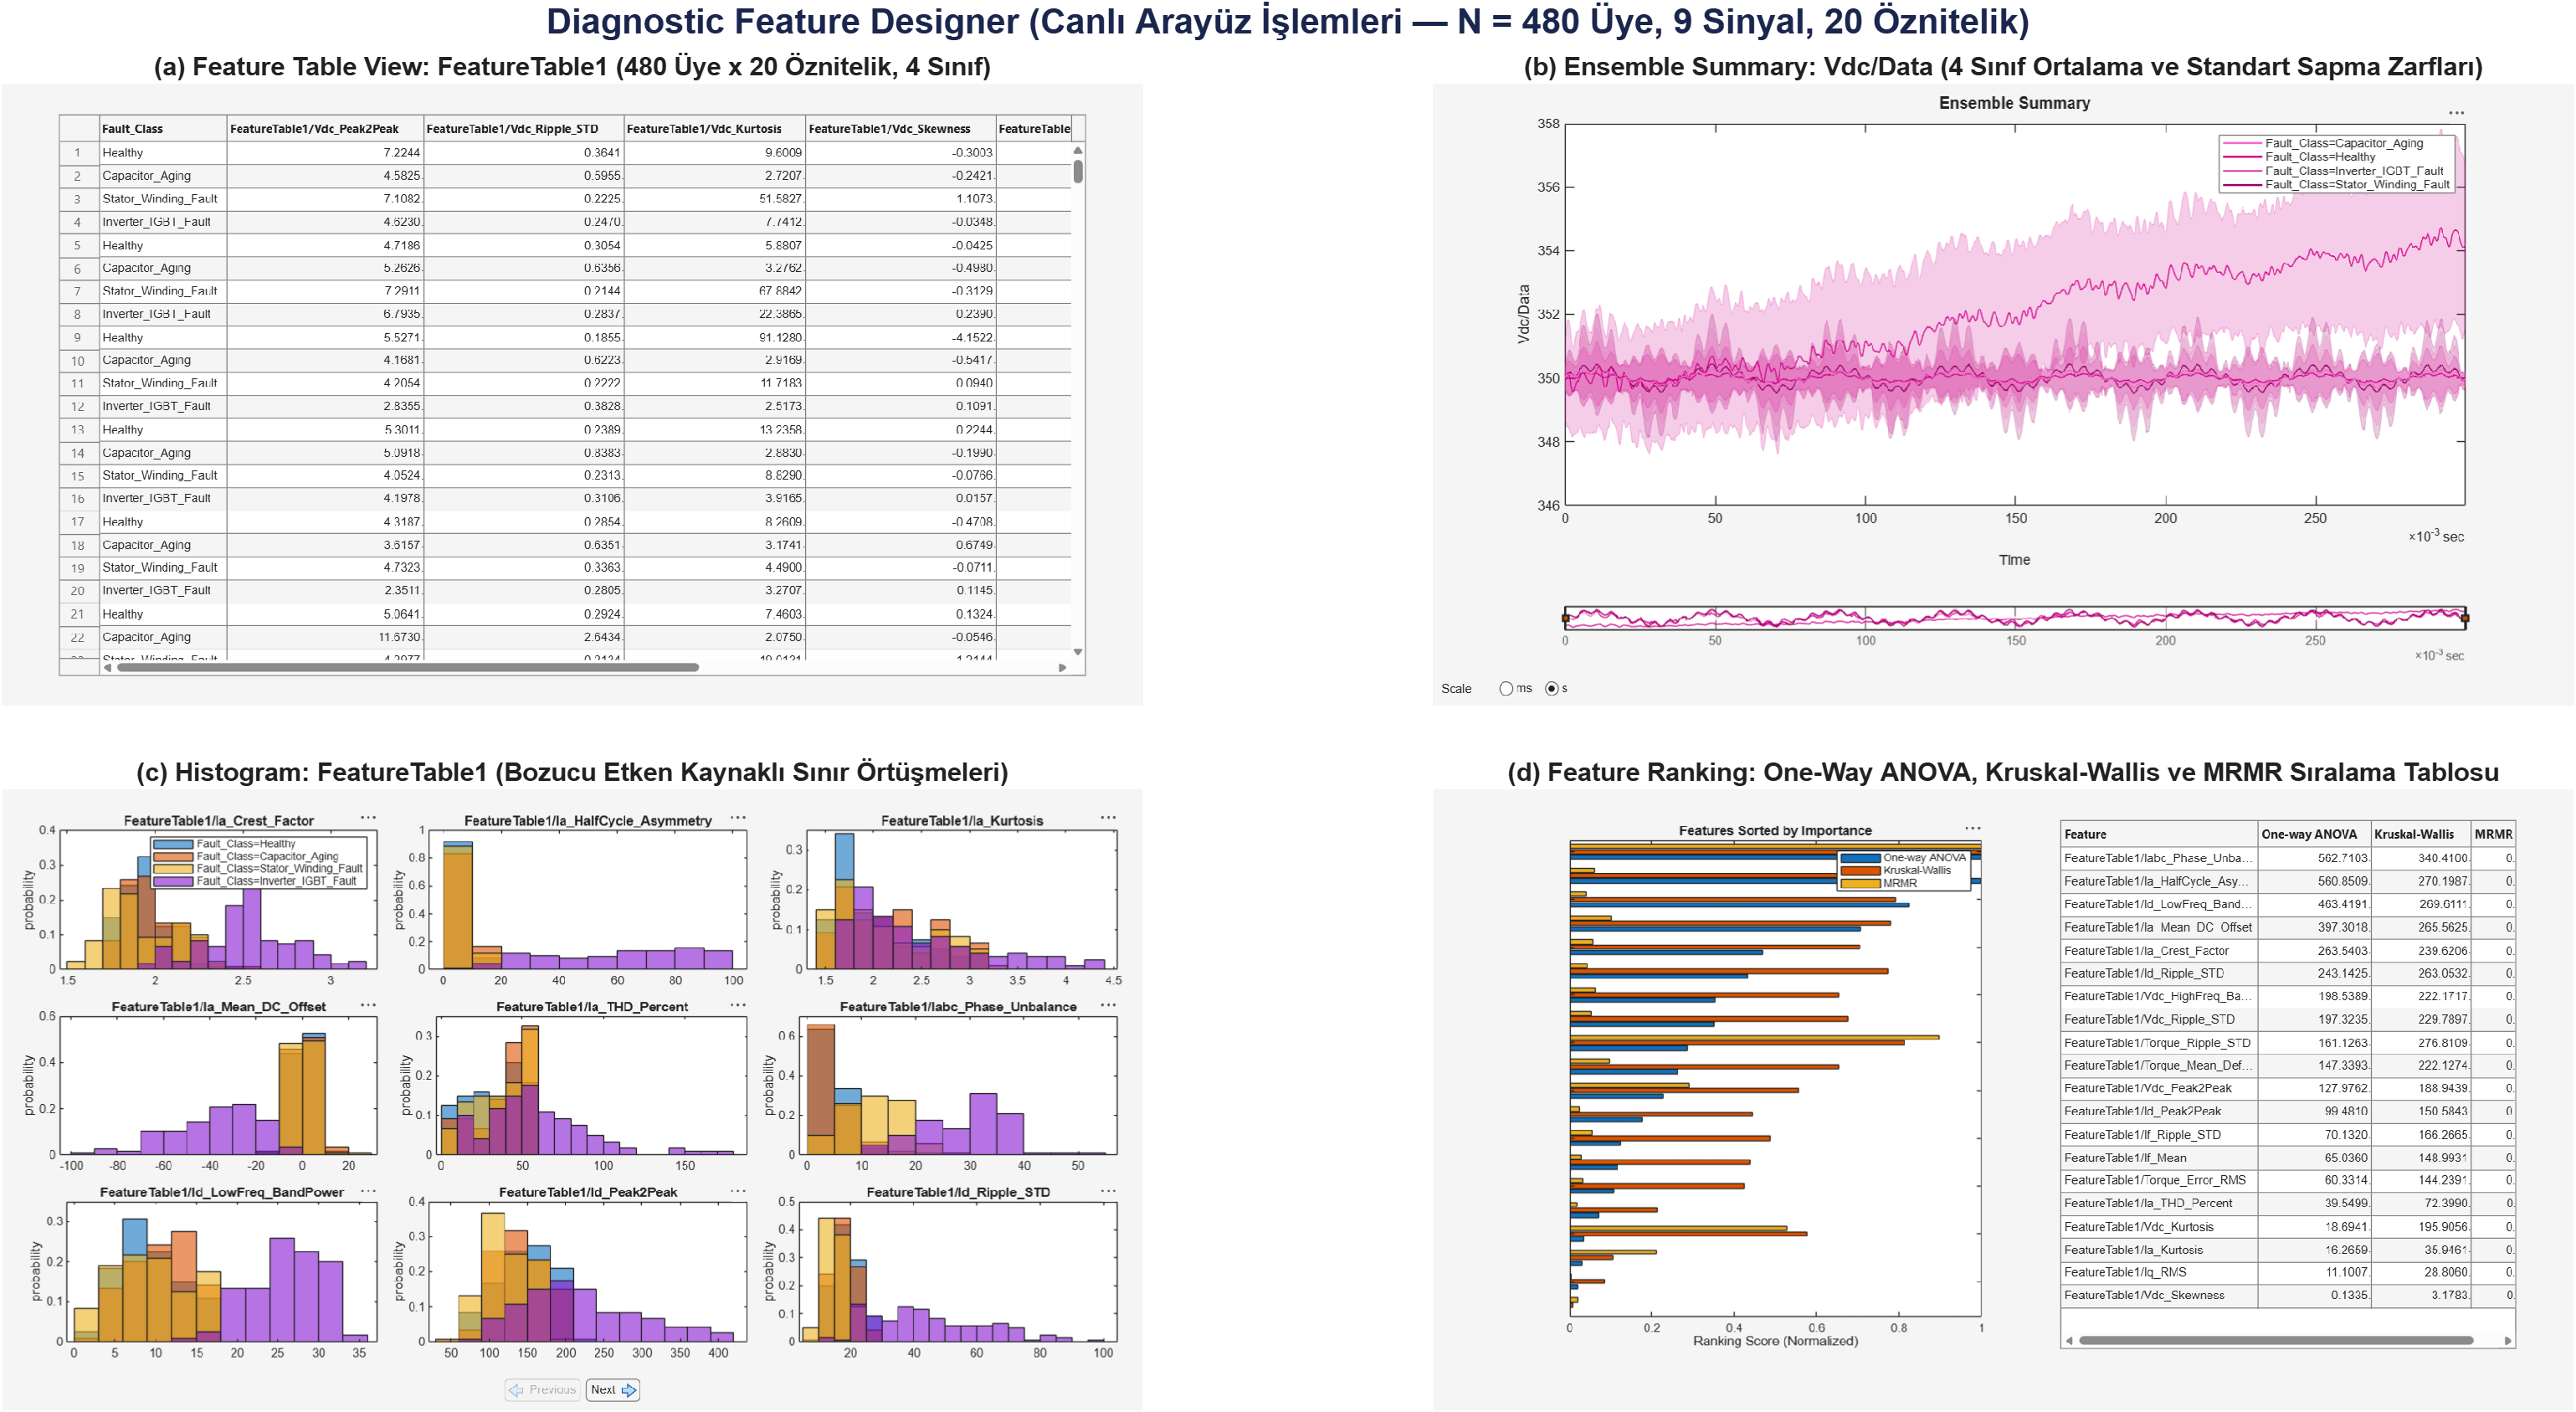

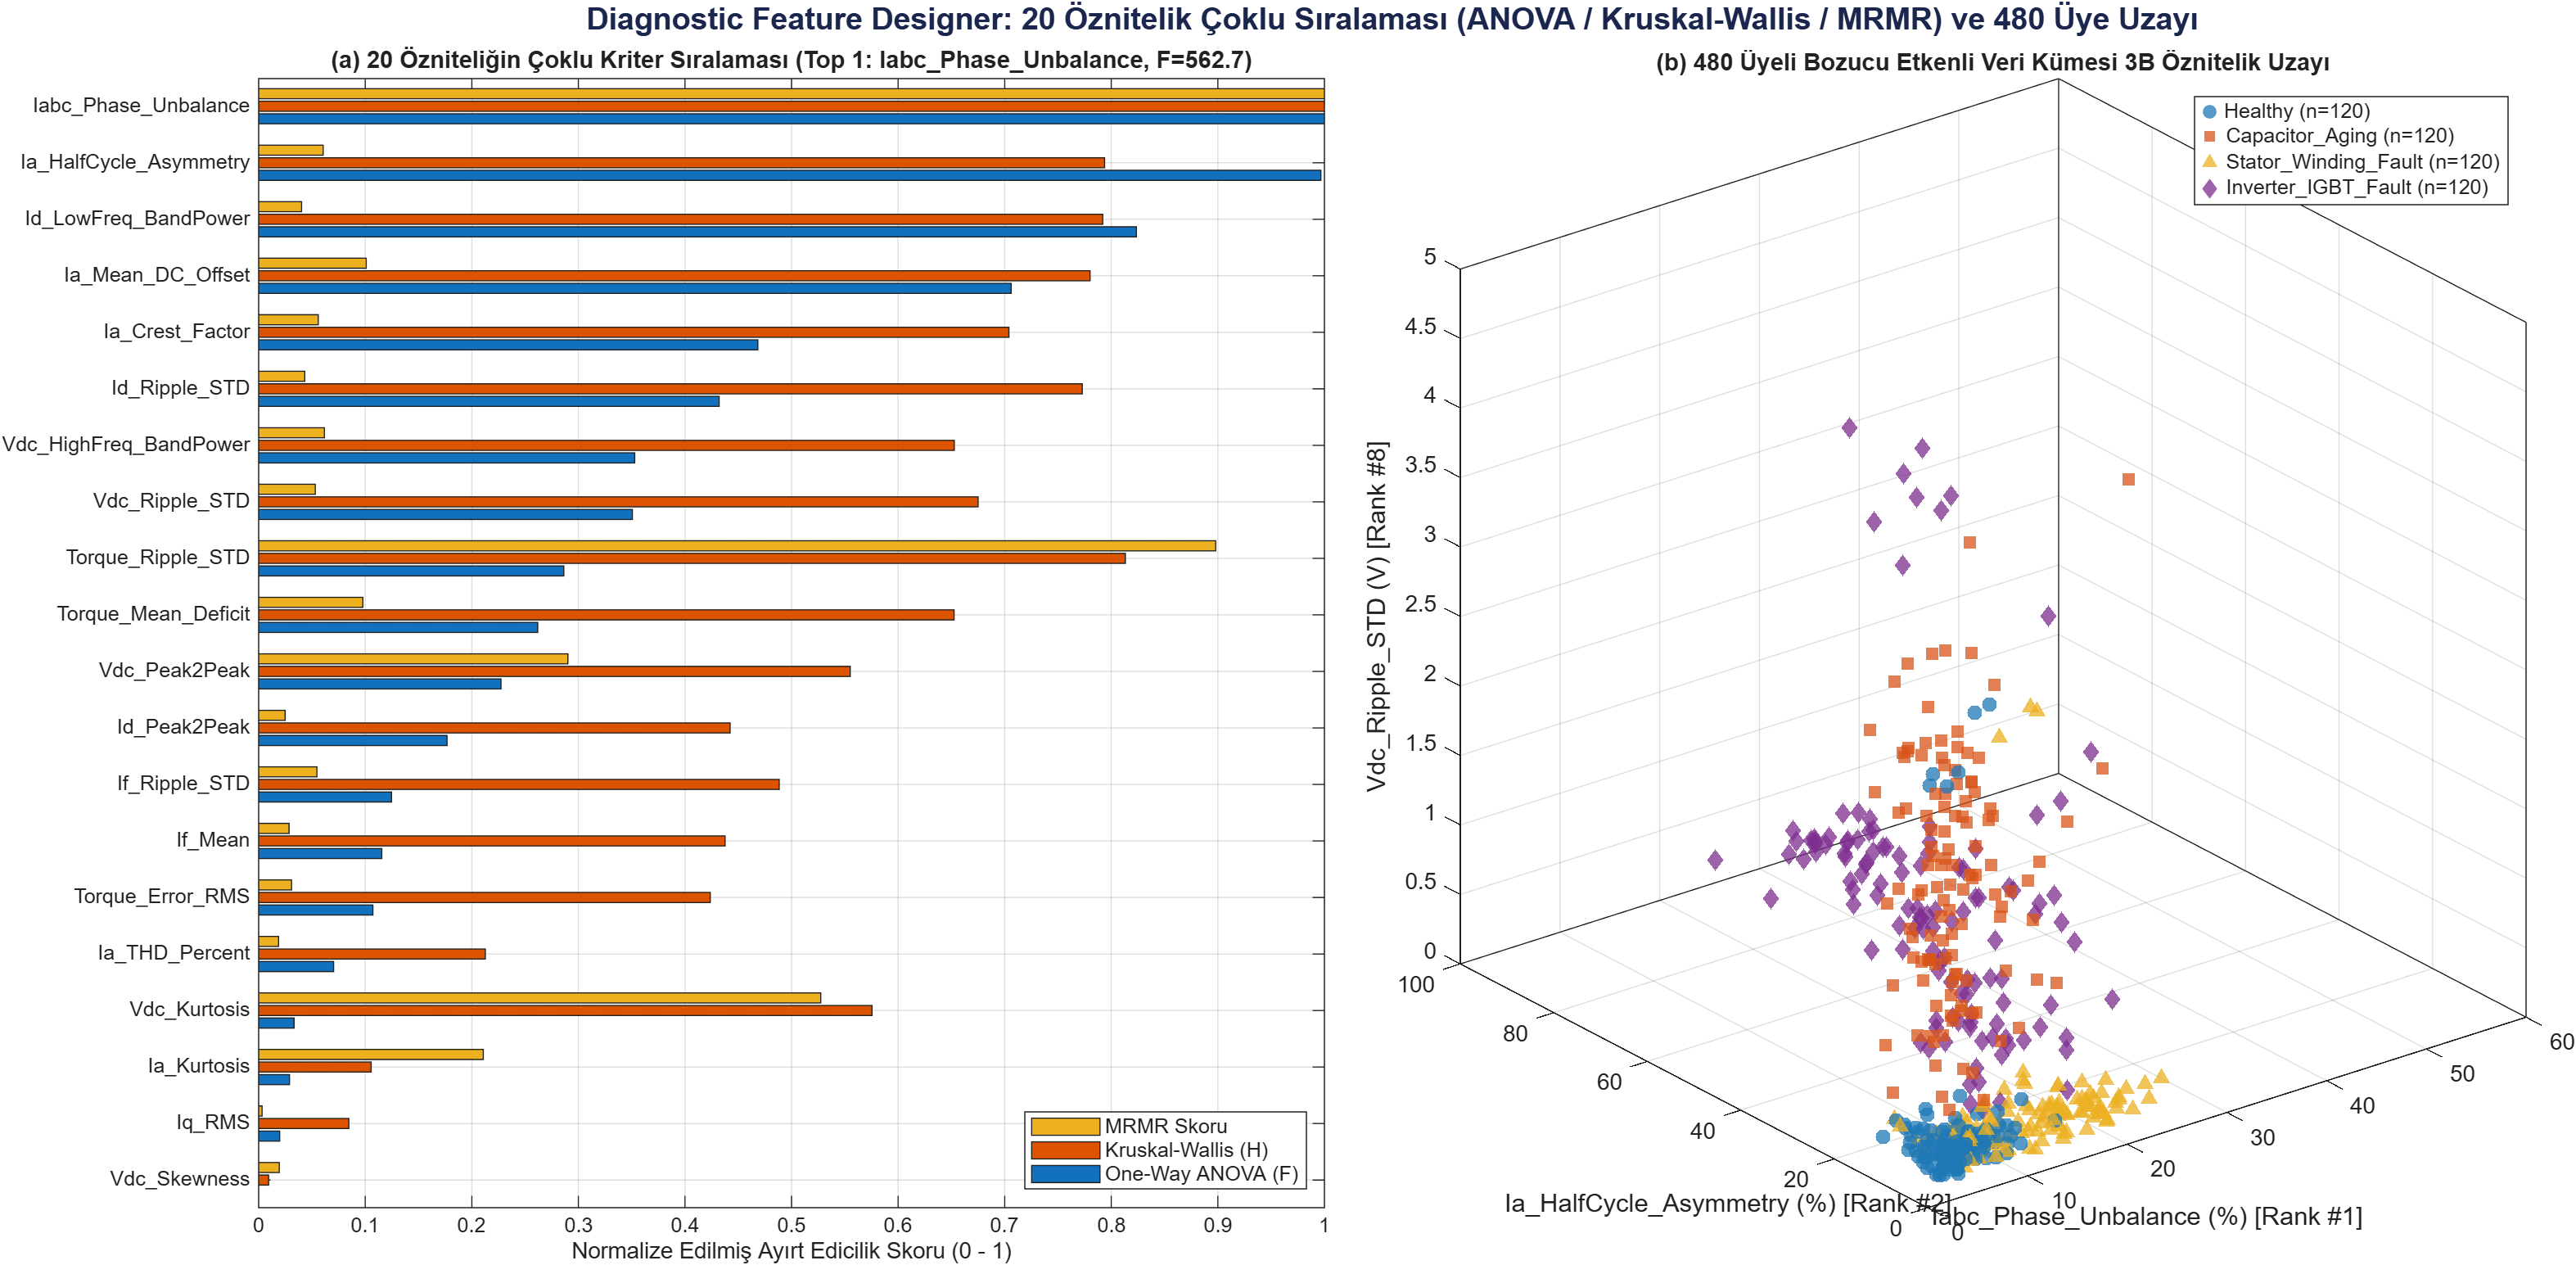

% 20 Teshis Ozniteliginin Coklu Kriter Siralamasini (ANOVA F-Stat, Kruskal-Wallis, MRMR) MATLAB Table olarak goster
Feature_Ranking_Table

Feature_Ranking_Table = 20×5 table
    Rank          Feature_Name          ANOVA_F_Score    KruskalWallis_Score    MRMR_Score
    ____    ________________________    _____________    ___________________    __________

      1     "Iabc_Phase_Unbalance"         562.71              340.41             0.60783 
      2     "Ia_HalfCycle_Asymmetry"       560.85               270.2            0.036773 
      3     "Id_LowFreq_BandPower"         463.42              269.61            0.024466 
      4     "Ia_Mean_DC_Offset"             397.3              265.56            0.061367 
      5     "Ia_Crest_Factor"              263.54              239.62            0.033983 
      6     "Id_Ripple_STD"                243.14              263.05            0.026266 
      7     "Vdc_HighFreq_BandPower"       198.54              222.17            0.037508 
      8     "Vdc_Ripple_STD"               197.32              229.79            0.032282 
      9     "Torque_Ripple_STD"            161.13     

## BÖLÜM 4 (ADIM 7 & 8): Çok-Sınıflı Yapay Zeka Arıza Teşhis Modellerinin Eğitimi ve Canlı Testi

## 4.1. Adım 7: Classification Learner "All" (35 Model) Eğitimi ve 5-Katlı Çapraz Doğrulama (Cross-Validation)

Sıralamada en yüksek ayırt edicilik skoruna sahip ilk 12 öznitelik (`top_features`) ve tüm 20 öznitelik kullanılarak 480 bozucu etkenli ensemble üyesi üzerinde **Classification Learner** galerisindeki **tüm 35 sınıflandırma modeli ("All")** eğitilmiş ve **5-Katlı Çapraz Doğrulama (5-Fold CV)** ile test edilmiştir:

- **Classification Learner "All" (35 Model — En İyi 12 Öznitelik Oturumu** `PdM_ClassificationLearner_Oturumu.mat`**):** #1 Wide Neural Network: **%97.50 (468 / 480 Doğru)**, #2 Narrow Neural Network: **%96.67 (464 / 480)**, #3 Residual DL Network: **%96.67 (464 / 480)**, #4 Efficient Logistic Regression: **%96.46 (463 / 480)**, #5 Medium / Trilayered Neural Network: **%96.25 (462 / 480)**, #7 Efficient Linear SVM & Bagged Trees: **%96.04 (461 / 480)**.

- **Classification Learner "All" (35 Model — Tüm 20 Öznitelik Oturumu** `PdM_ClassificationLearner_Full20_Oturumu.mat`**):** #1 Quadratic Discriminant: **%97.08 (466 / 480 Doğru)**, #2 Narrow & Trilayered Neural Network: **%96.88 (465 / 480)**, #4 Medium & Wide Neural Network: **%96.46 (463 / 480)**, #6 Efficient Linear SVM & Bagged Trees: **%96.25 (462 / 480)**.

- **Komut Satırı Referans Modelleri ****(**`PdM_Trained_Classifier.mat`**):** Torbalı Karar Ağaçları (`Mdl_RandomForest` — 80 Ağaç, MaxSplits=25): **%94.37 (453 / 480)** ve Çok-Sınıflı Gauss SVM (`Mdl_MultiSVM`): **%89.17 (428 / 480)**.

Eğitilmiş 35 modelin tamamını **veri seçme ekranı çıkmadan** etkileşimli **Classification Learner** arayüzünde doğrudan hazır açmak için:

- **En İyi 12 Öznitelik (35 Eğitilmiş Model Hazır):** `classificationLearner(fullfile(pwd, 'Mat_Dosyalari', 'PdM_ClassificationLearner_Oturumu.mat'))`

- **Tüm 20 Öznitelik (35 Eğitilmiş Model Hazır):** `classificationLearner(fullfile(pwd, 'Mat_Dosyalari', 'PdM_ClassificationLearner_Full20_Oturumu.mat'))`

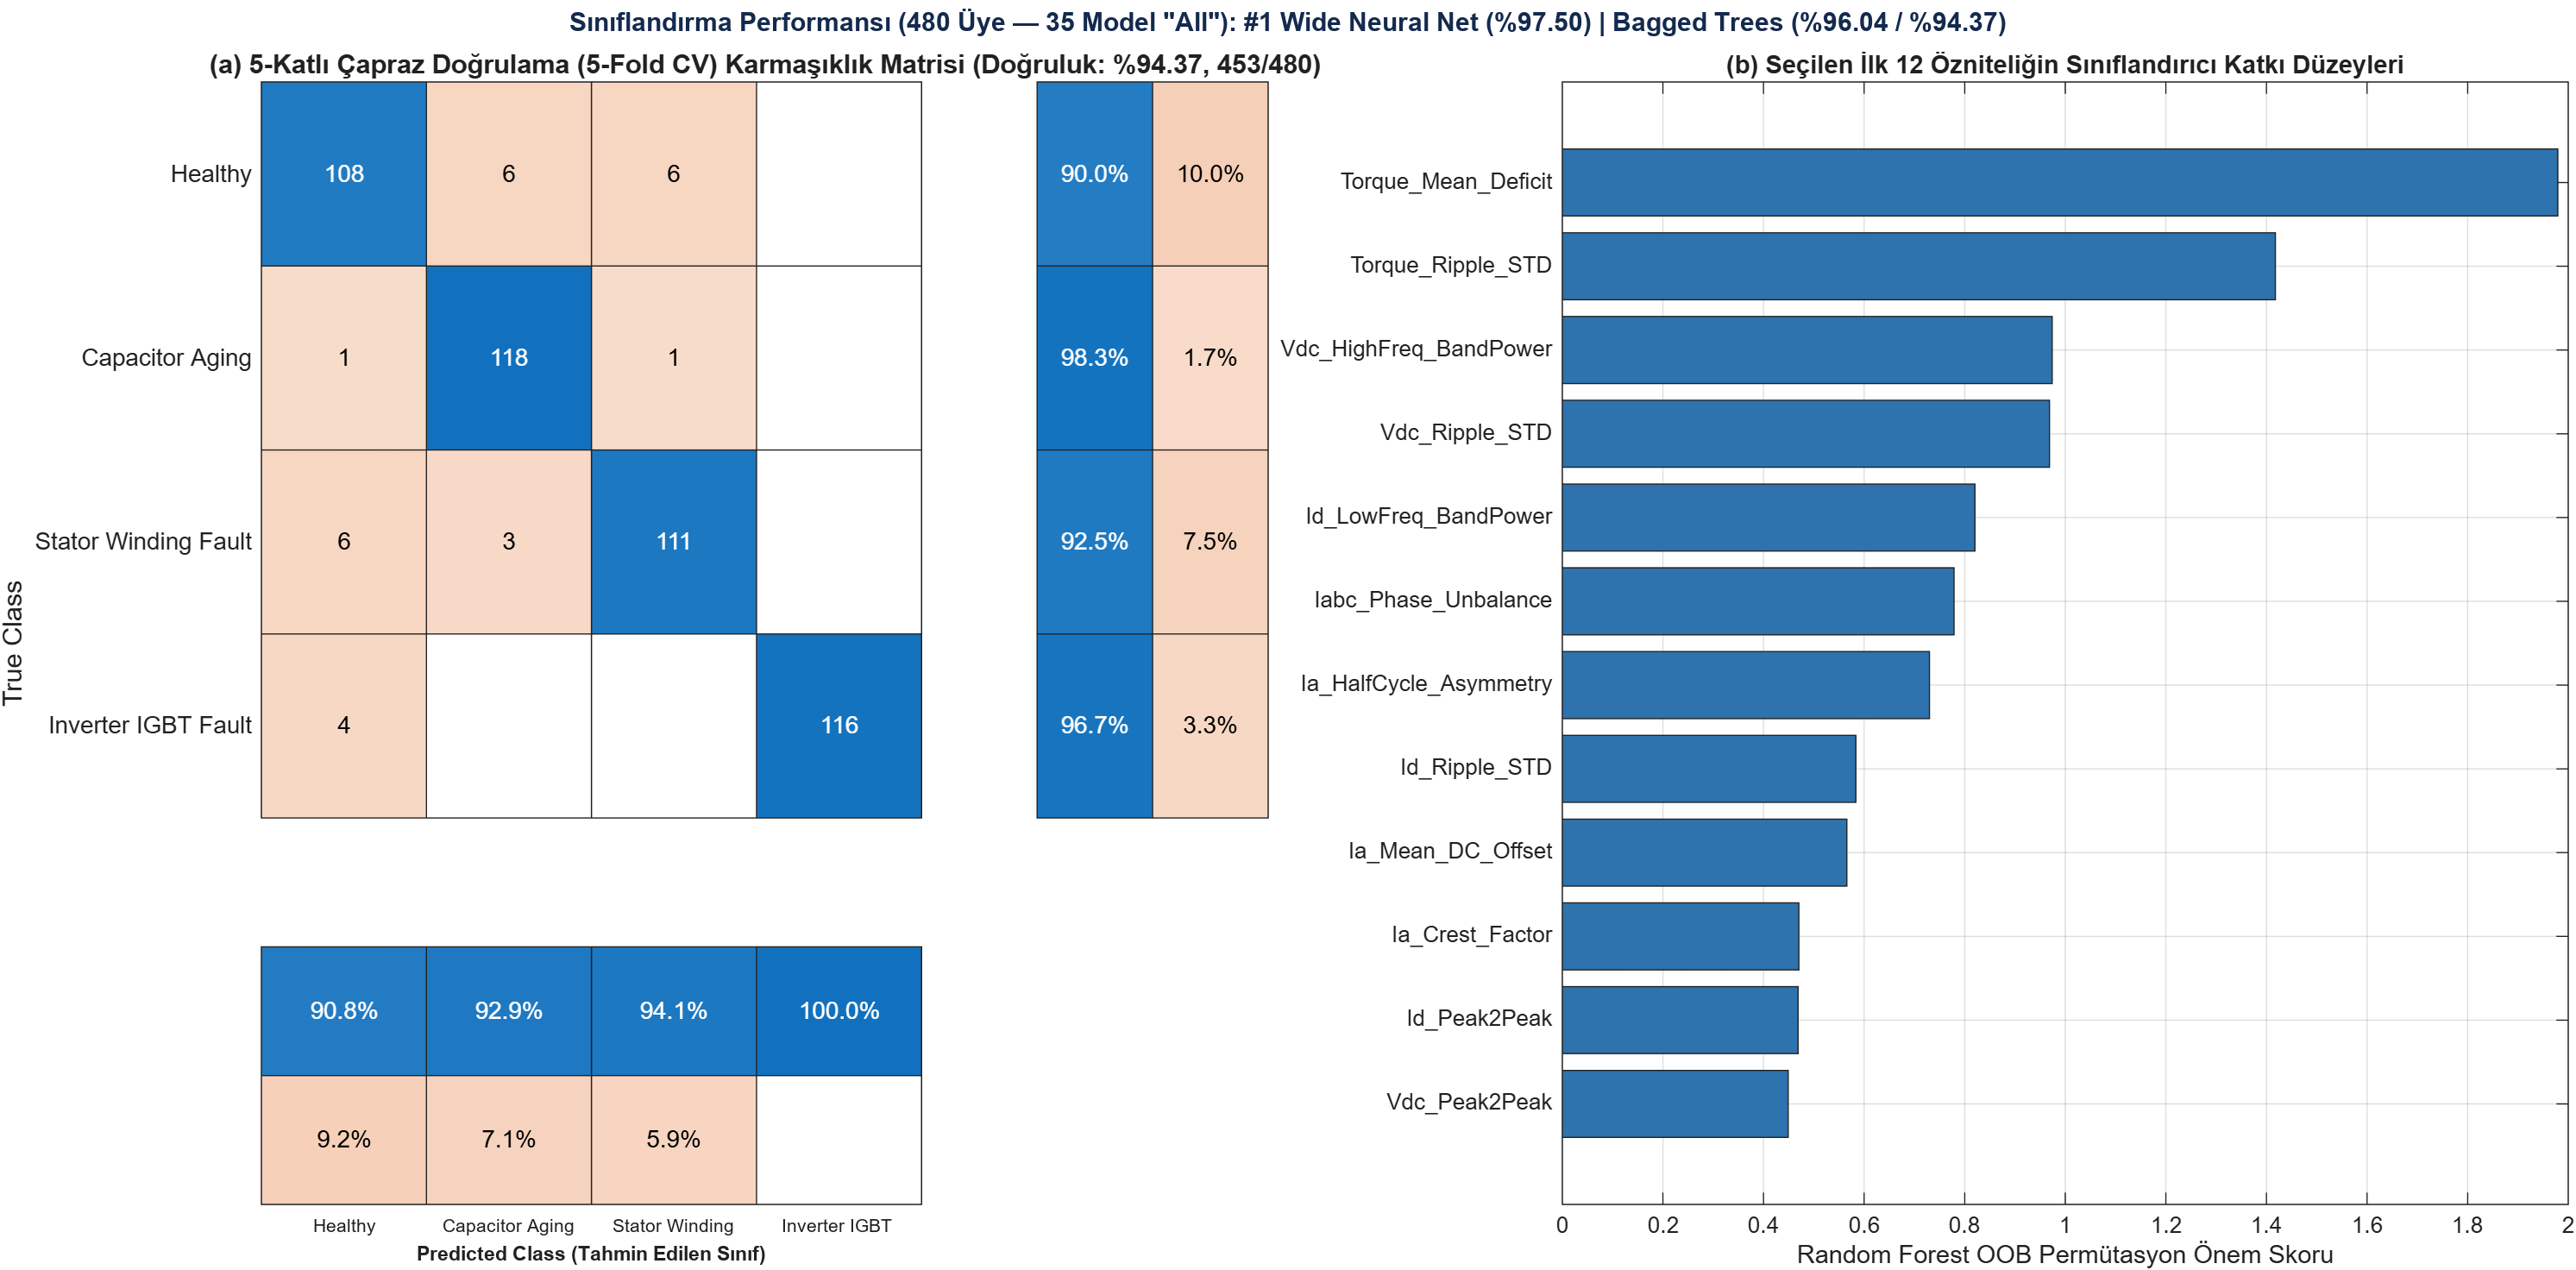

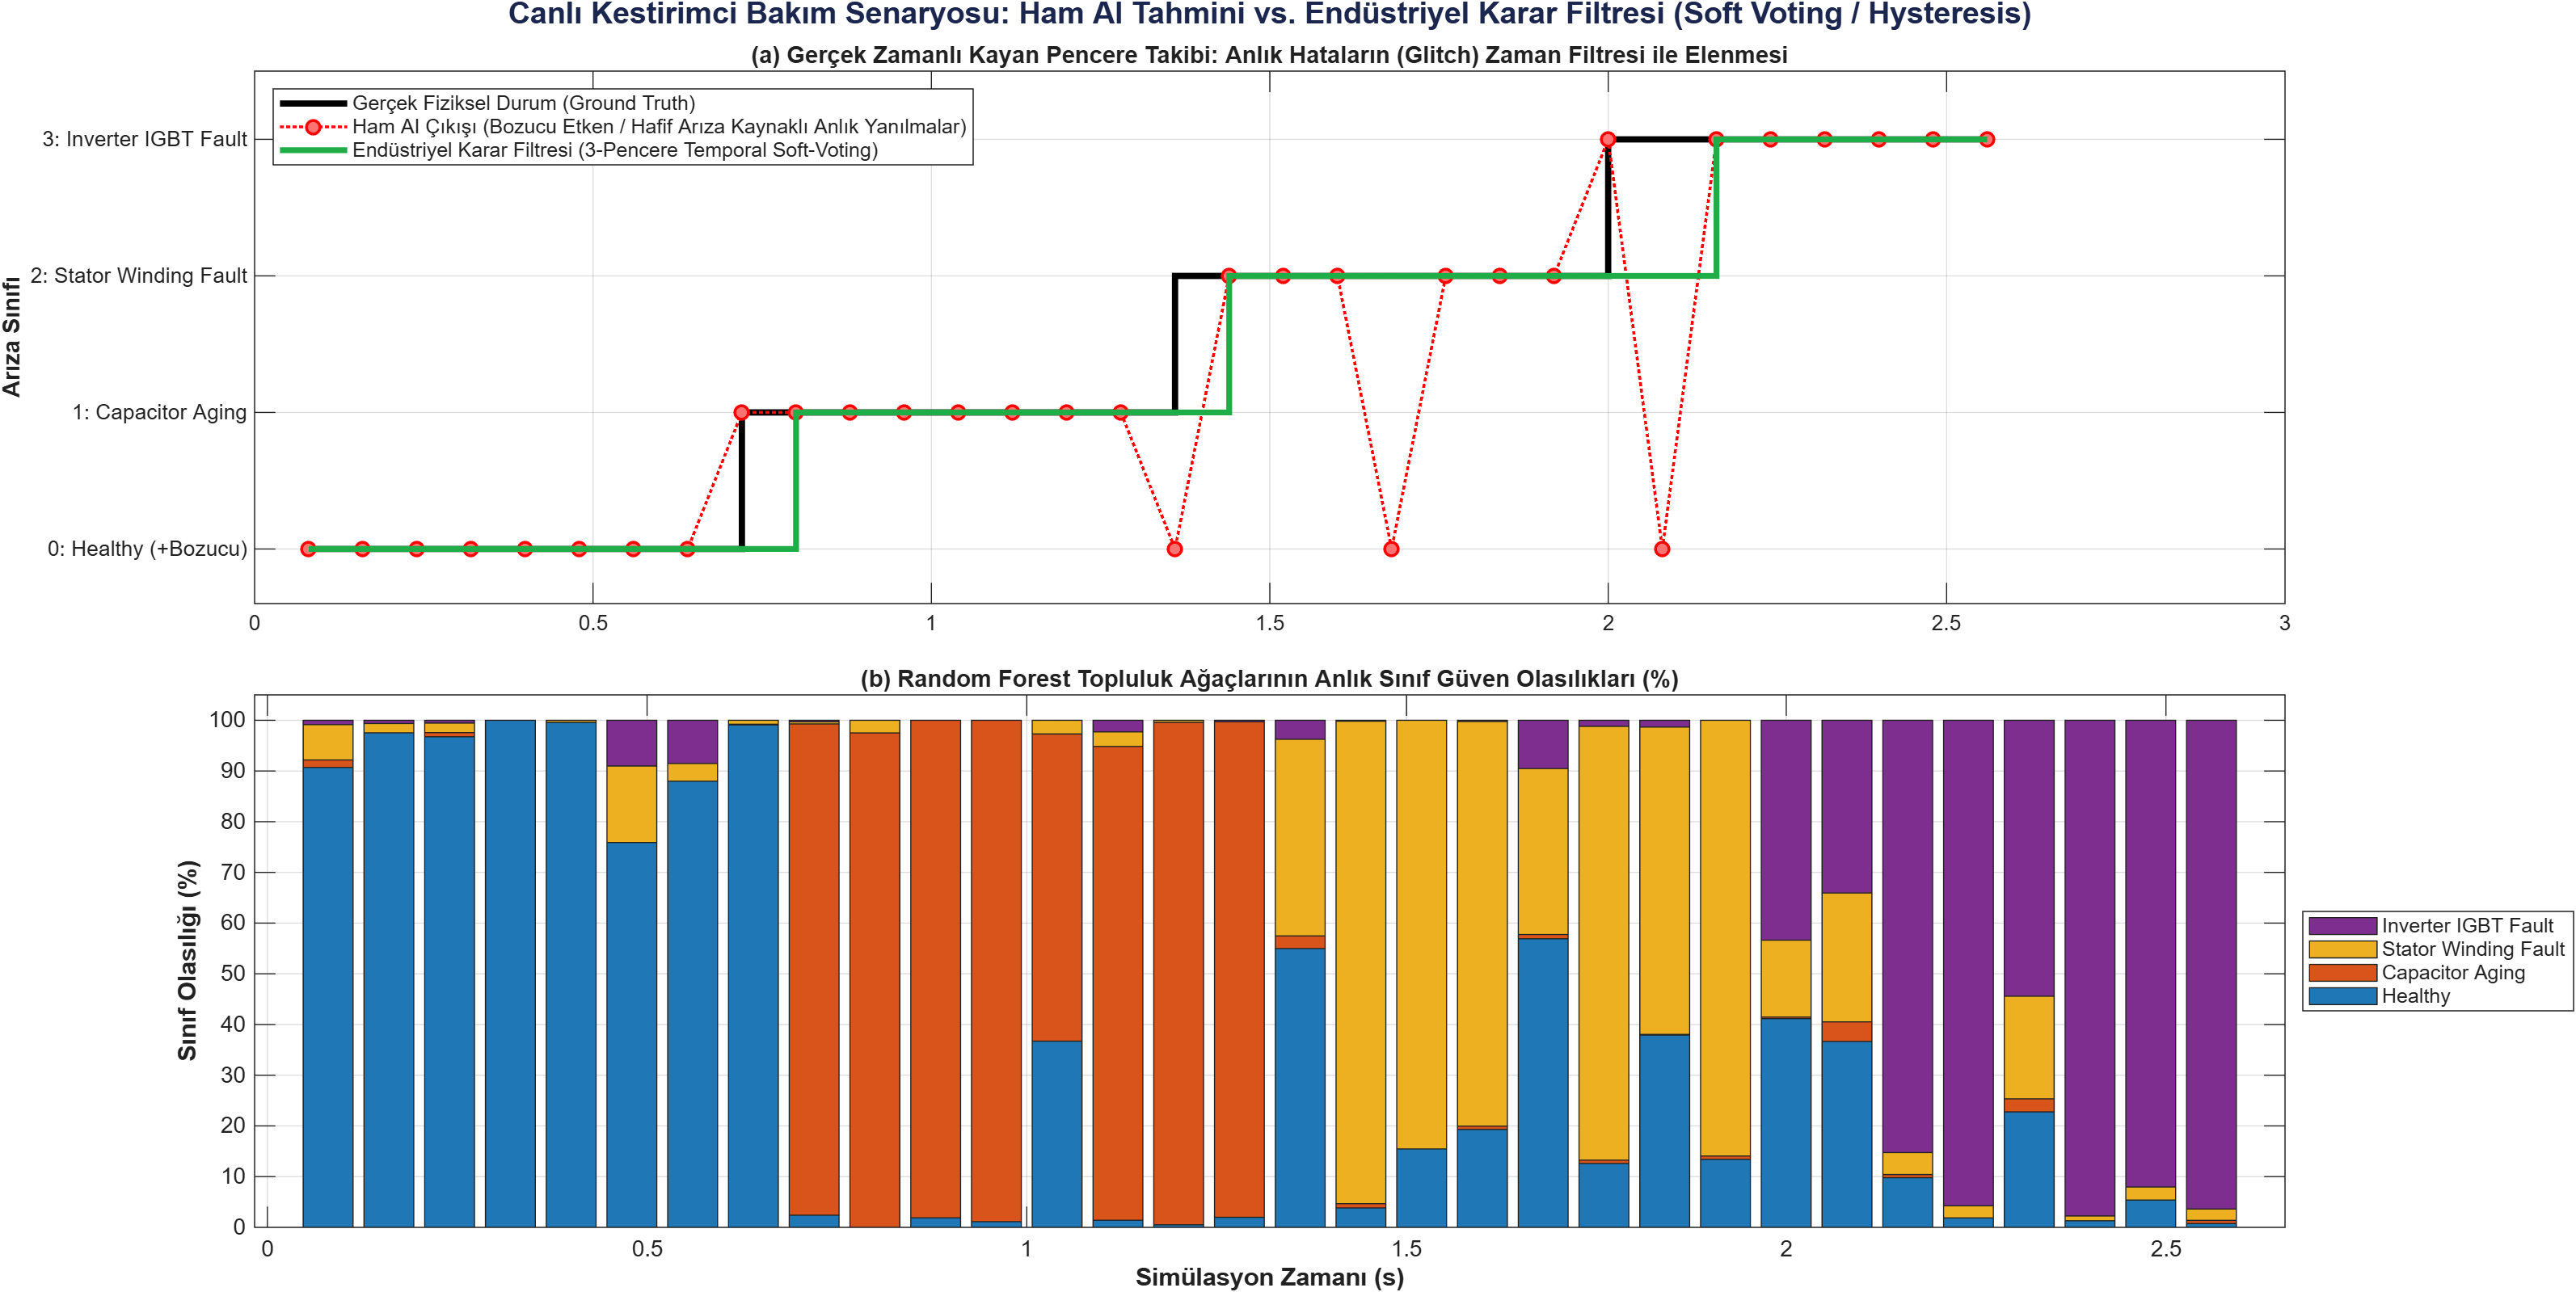

% Siniflandirma modellerinin 5-Katli Capraz Dogrulama (5-Fold CV) karsilastirma tablosu
Model_Adi = {
    '1. Wide Neural Network (Classification Learner All - Model 1.31)';
    '2. Quadratic Discriminant (Classification Learner Full 20 - Model 1.6)';
    '3. Narrow Neural Network (Classification Learner All - Model 1.29)';
    '4. Residual Neural Network / DL (Classification Learner All - Model 1.34)';
    '5. Bagged Trees / Random Forest (Classification Learner All - Model 1.25)';
    '6. Bagged Trees Komut Satiri Modeli (Mdl_RandomForest - 80 Agac)';
    '7. Multi-Class Gaussian SVM (Mdl_MultiSVM - ECOC)'};
Oznitelik_Seti = {'Top 12 Oznitelik'; 'Tum 20 Oznitelik'; 'Top 12 Oznitelik'; 'Top 12 Oznitelik'; 'Top 12 Oznitelik'; 'Top 12 Oznitelik'; 'Top 12 Oznitelik'};
Dogru_Tahmin_Sayisi = [468; 466; 464; 464; 461; 453; 428];
Dogruluk_Yuzde = round([97.50; 97.08; 96.67; 96.67; 96.04; cv_acc_percent; svm_acc_percent], 2);

Model_Basarim_Tablosu = table(Model_Adi, Oznitelik_Seti, Dogru_Tahmin_Sayisi, Dogruluk_Yuzde)

Model_Basarim_Tablosu = 7×4 table
                                      Model_Adi                                         Oznitelik_Seti       Dogru_Tahmin_Sayisi    Dogruluk_Yuzde
    _____________________________________________________________________________    ____________________    ___________________    ______________

    {'1. Wide Neural Network (Classification Learner All - Model 1.31)'         }    {'Top 12 Oznitelik'}            468                 97.5     
    {'2. Quadratic Discriminant (Classification Learner Full 20 - Model 1.6)'   }    {'Tum 20 Oznitelik'}            466                97.08     
    {'3. Narrow Neural Network (Classification Learner All - Model 1.29)'       }    {'Top 12 Oznitelik'}            464                96.67     
    {'4. Residual Neural Network / DL (Classification Learner All - Model 1.34)'}    {'Top 12 Oznitelik'}            464                96.67     
    {'5. Bagged Trees / Random Forest (Classification Learner All - Model 1.25)'}  


% Egitilmis Random Forest modeli ile 4 siniftan ornek uyeler uzerinde canli ariza teshisi testi
ornek_indisler = [1, 2, 3, 4, 241, 242, 243, 244]; % Interleaved tablodan 2'ser ornek uye
X_ornek = table2array(PdM_Feature_Table(ornek_indisler, top_features));
gercek_sinif = string(PdM_Feature_Table.Fault_Class(ornek_indisler));
siddet_pct   = round(PdM_Feature_Table.Fault_Severity_Pct(ornek_indisler), 1);
snr_val      = round(PdM_Feature_Table.SNR_dB(ornek_indisler), 1);
[tahmin_sinif_cat, olasilik_skorlari] = predict(Mdl_RandomForest, X_ornek);
tahmin_sinif  = string(tahmin_sinif_cat);
guven_yuzdesi = round(max(olasilik_skorlari, [], 2) * 100, 2);

Canli_Teshis_Tablosu = table(ornek_indisler', gercek_sinif, tahmin_sinif, siddet_pct, snr_val, guven_yuzdesi, ...
    'VariableNames', {'Member_ID', 'Gercek_Sinif', 'Tahmin_Edilen_Sinif', 'Ariza_Siddeti_Pct', 'SNR_dB', 'Guven_Skoru_Pct'})

Canli_Teshis_Tablosu = 8×6 table
    Member_ID         Gercek_Sinif          Tahmin_Edilen_Sinif      Ariza_Siddeti_Pct    SNR_dB    Guven_Skoru_Pct
    _________    ______________________    ______________________    _________________    ______    _______________

         1       "Healthy"                 "Healthy"                        7.8            19.9           90.7     
         2       "Capacitor_Aging"         "Capacitor_Aging"                 18            15.1          96.88     
         3       "Stator_Winding_Fault"    "Healthy"                         24            17.4          54.98     
         4       "Inverter_IGBT_Fault"     "Inverter_IGBT_Fault"           26.6            12.3          43.37     
       241       "Healthy"                 "Healthy"                        4.5            18.1          95.22     
       242       "Capacitor_Aging"         "Capacitor_Aging"               90.2            14.9          97.42     
       243       "Stator_Winding_Fault

## 4.2. Adım 8: Simulink Üzerindeki Canlı Arıza Seçim Butonları ve Hızlı Komut Rehberi

`SMTorqueControl_PdM.slx` modelinin en üst şeridine **5 adet renkli etkileşimli arıza/bozucu seçim butonu** ve **1 adet Aktif Mod Göstergesi** yerleştirilmiştir:

- **Simulink Üzerinden Canlı Değiştirme (Çift Tıklama):** Model açıkken veya simülasyon çalışırken üstteki **1. SAĞLIKLI MOD**, **2. BOZUCU ETKENLİ**, **3. KAPASİTÖR ARIZASI**, **4. STATOR SARGI ARIZASI** veya **5. IGBT AÇIK DEVRE** bloklarından herhangi birine çift tıkladığınızda; ilgili tüm Workspace değişkenleri ve Simulink blok parametreleri (`set_param` ve `SimulationCommand: update`) otomatik olarak atanır, sağ üstteki durum göstergesi güncellenir.

Alternatif olarak çalışma uzayından (Command Window) manuel atama yapmak isterseniz aşağıdaki komutları da kullanabilirsiniz:

- **1. Sağlıklı (Nominal) Mod:**  `Cdc_PdM = Cdc; ESR_PdM = 1e-3; Rbat_PdM = 1e-3; Rs_PdM = Rs; Lad_PdM = Lad; Rfd_PdM = Rfd; Gate_Fault_Mask = [1;1;1;1;1;1]; Stator_Unbalance_Gain = [1;1;1]; Sensor_Offset_Drift_PdM = [0;0;0]; Load_Scale_PdM = 1.0;`

- **2. Bozucu Etkenli Sağlıklı Mod (Sensör DC Ofset Kayması + Aşırı Yük):**  `Sensor_Offset_Drift_PdM = [12; -6; -6]; Stator_Unbalance_Gain = [1.04; 0.98; 0.98]; Load_Scale_PdM = 1.25; Gate_Fault_Mask = [1;1;1;1;1;1];`

- **3. DC-Link Kapasitör Yaşlanması (Capacitor Aging):**  `Cdc_PdM = 0.30*Cdc; ESR_PdM = 0.08; Rbat_PdM = 0.18; Gate_Fault_Mask = [1;1;1;1;1;1]; Stator_Unbalance_Gain = [1;1;1]; Sensor_Offset_Drift_PdM = [0;0;0];`

- **4. Stator Sargı Arızası ve Faz Asimetrisi (Stator Winding Fault):**  `Rs_PdM = 3.5*Rs; Lad_PdM = 0.82*Lad; Rfd_PdM = 1.4*Rfd; Stator_Unbalance_Gain = [1.12;0.94;0.94]; Gate_Fault_Mask = [1;1;1;1;1;1]; Sensor_Offset_Drift_PdM = [0;0;0];`

- **5. İnverter A-Fazı Üst IGBT Açık Devre Arızası (Inverter IGBT Fault):**  `Gate_Fault_Mask = [0;1;1;1;1;1]; Cdc_PdM = Cdc; Rs_PdM = Rs; Stator_Unbalance_Gain = [1;1;1]; Sensor_Offset_Drift_PdM = [0;0;0];`